## (POC 1)

% set input and output path
input_path = '../../../biosensor/data/raw';
output_path = '../../../matlab/output';

% input file
input_file = '010756_09112024Test01';
input_file_delimiter = '\t';

% read data
full_path = fullfile(input_path, input_file); % compute full path
data = readtable(full_path, 'Delimiter', input_file_delimiter); % load data

colmap = jet(8);
colmap2 = jet(10);

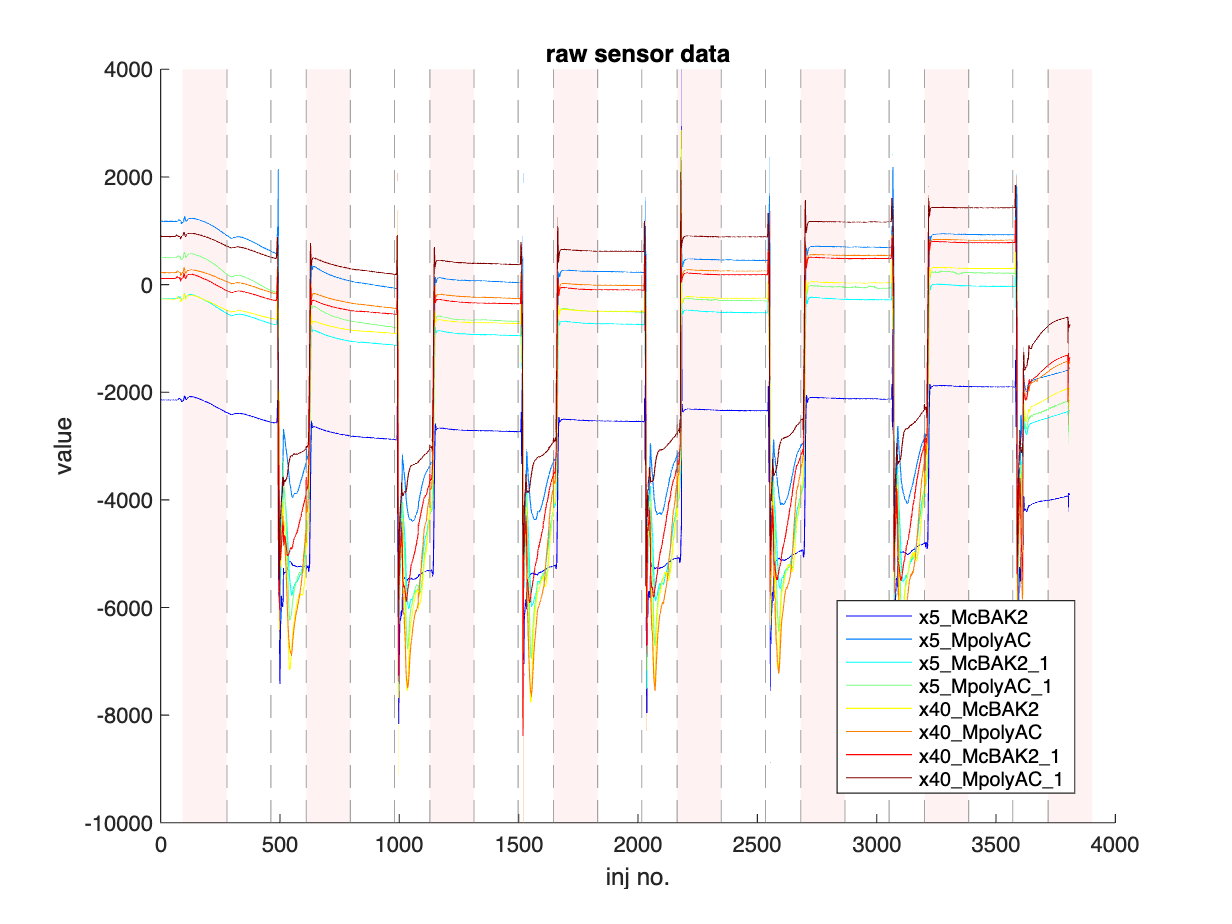

figure; hold on; % display raw sensor data
for i = 1:8; plot(data{:, i+4}, Color = colmap(i, :), DisplayName = data.Properties.VariableNames{i+4}); end
xline(find(diff(data.Val_) ~= 0) + 1, '--', Color = [0.5, 0.5, 0.5], HandleVisibility = 'off');
for i = 1:8; xregion(92 + (i-1)*518, 92+(i-1)*518 + 185, FaceColor = 'r', FaceAlpha = 0.05, EdgeColor = 'none', HandleVisibility = 'off'); end
xlabel("inj no."); ylabel("value"); title("raw sensor data"); legend('show', Interpreter = 'none', Location = 'best');

% how long are each val cycles?
val_cycl_leng_array = diff(find(diff(data.Val_) ~= 0) + 1);
val_cycl_leng_matrix = reshape(distances(1:3 * (floor(length(val_cycl_leng_array)/3)) ), 3, []).';

Incorrect number or types of inputs or outputs for function distances.

disp(val_cycl_leng_matrix);

Checking if time stamps are regular.

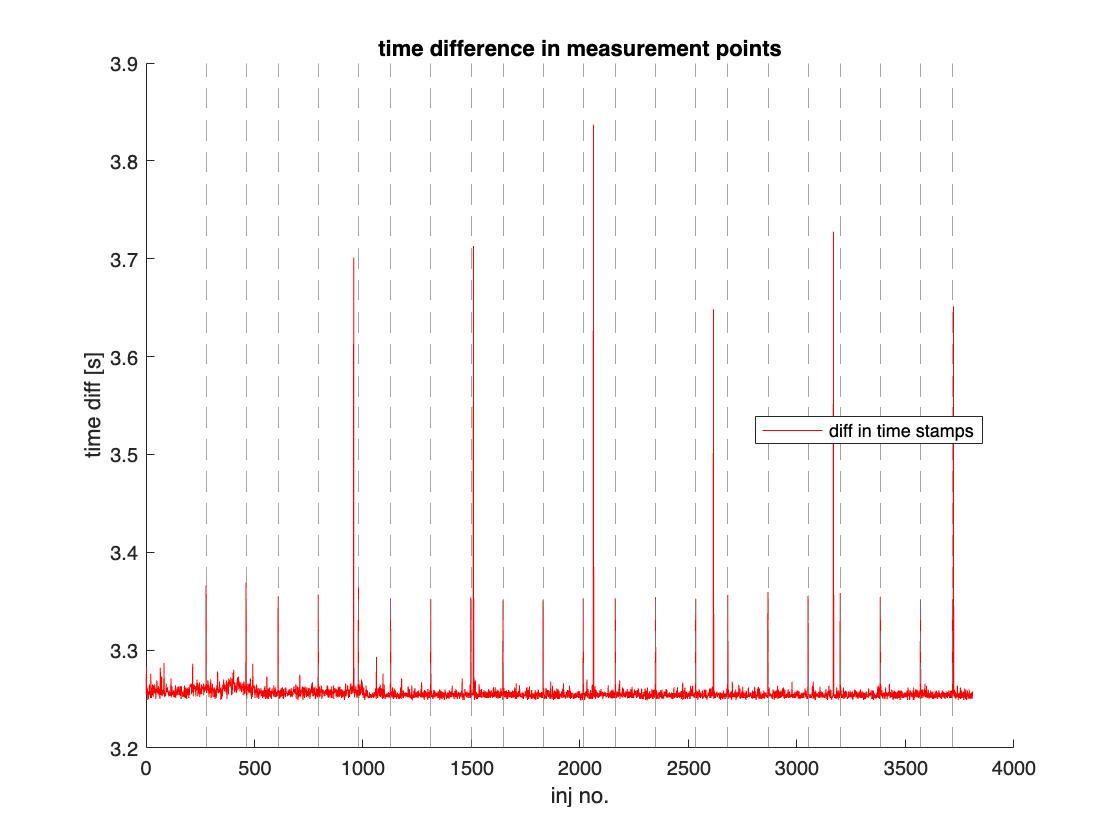

figure; hold on; % display time diff
plot(1:length(data.T_s_)-1, diff(data.T_s_), '-r', 'DisplayName', 'diff in time stamps');
xline(find(diff(data.Val_) ~= 0) + 1, '--', 'Color', [0.5, 0.5, 0.5], 'HandleVisibility', 'off');
xlabel('inj no.'); ylabel('time diff [s]'); title("time difference in measurement points"); legend('show', 'Interpreter', 'none', 'Location', 'best');

[R,P] = corrcoef(1:length(data.T_s_)-1, diff(data.T_s_));
disp("corr coeff: " + R(1,2) + ", p-value: " + P(1,2));

corr coeff: -0.060846, p-value: 0.00017161


time_diff_mean = mean(diff(data.T_s_));
disp("mean: " + time_diff_mean);

mean: 3.2567


time_diff_range = range(diff(data.T_s_));
time_diff_sigma = std(diff(data.T_s_));
disp("max deviation: " + time_diff_range + ", std deviation: " + time_diff_sigma);

max deviation: 0.58838, std deviation: 0.020208


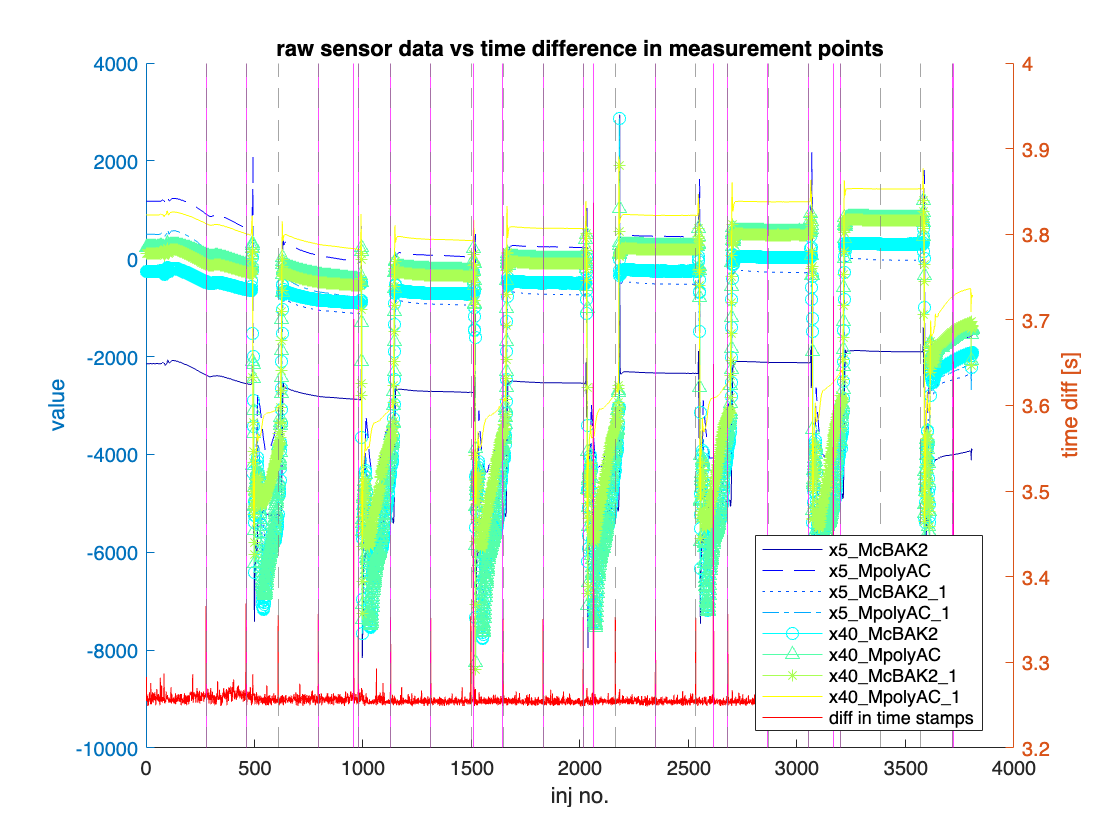

figure; hold on; % display raw sensor data and time diff
yyaxis left;
for i = 1:8; plot(data{:, i+4}, Color = colmap2(i, :), DisplayName = data.Properties.VariableNames{i+4}); end
xlabel("inj no."); ylabel("value");
yyaxis right;
plot(1:length(data.T_s_)-1, diff(data.T_s_), '-r', DisplayName = "diff in time stamps");
xline(find(diff(diff(data.T_s_)) > 0.1) + 1, '-m', HandleVisibility = 'off');
xline(find(diff(data.Val_) ~= 0) + 1, '--', Color = [0.5, 0.5, 0.5], HandleVisibility = 'off');
ylabel("time diff [s]"); title("raw sensor data vs time difference in measurement points"); legend('show', 'Interpreter', 'none', 'Location', 'best');

We want to see how the temperature behaves and if there are any irregularities.

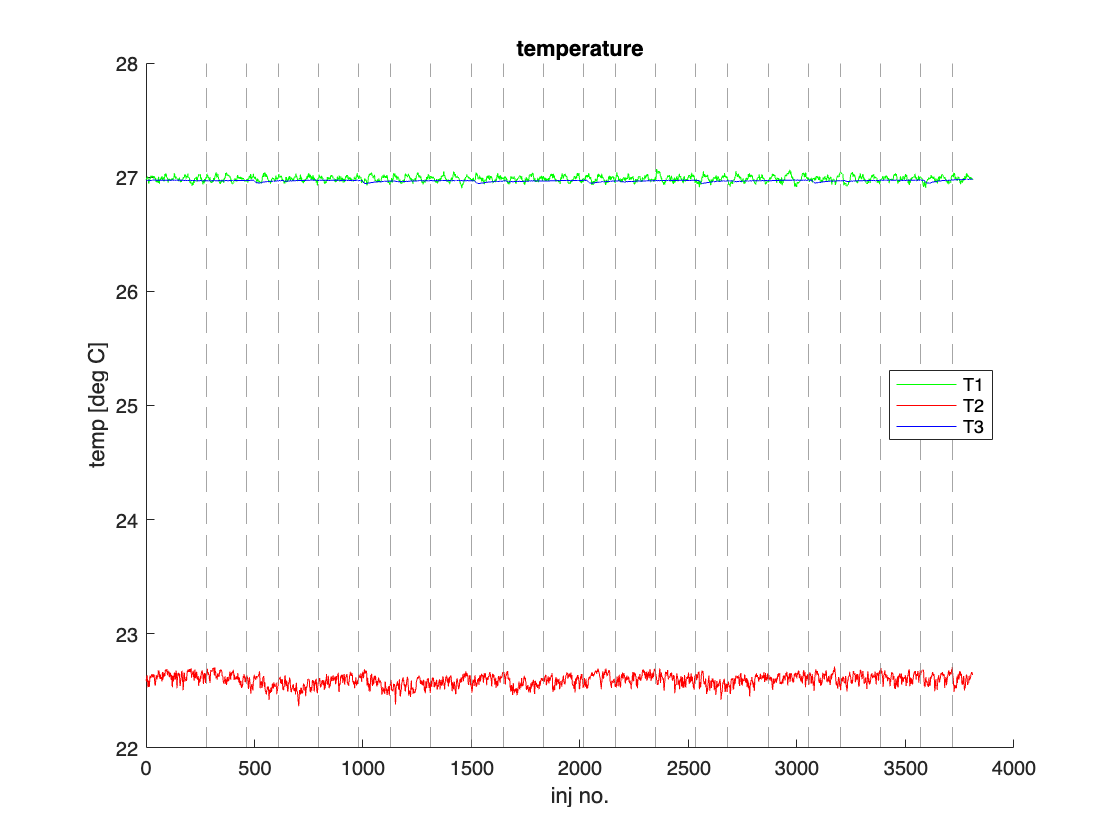

figure; hold on; % display temp data
plot(data.T1, '-g', DisplayName = "T1");
plot(data.T2, '-r', DisplayName = "T2");
plot(data.T3, '-b', DisplayName = "T3");
xline(find(diff(data.Val_) ~= 0) + 1, '--', Color = [0.5, 0.5, 0.5], HandleVisibility = 'off');
xlabel('inj no.'); ylabel('temp [deg C]'); title("temperature"); legend('show', 'Interpreter', 'none', 'Location', 'best');

for i = 1:3
    temp_sensor = string("T" + i);
    temp_mean = mean(data.(temp_sensor));
    temp_range = range(data.(temp_sensor)); temp_range_rel = temp_range/temp_mean;
    temp_sigma = std(data.(temp_sensor)); temp_sigma_rel = temp_sigma/temp_mean;
    disp(temp_sensor + ": mean: " + temp_mean + ...
        ", max deviation: " + temp_range + " (" + temp_range_rel*100 + " %)" + ...
        ", std deviation: " + temp_sigma + " (" + temp_sigma_rel*100 + " %)");
end

T1: mean: 26.986, max deviation: 0.16793 (0.62228 %), std deviation: 0.02437 (0.090305 %)
T2: mean: 22.5945, max deviation: 0.34822 (1.5412 %), std deviation: 0.050683 (0.22432 %)
T3: mean: 26.9673, max deviation: 0.039999 (0.14832 %), std deviation: 0.0066317 (0.024592 %)


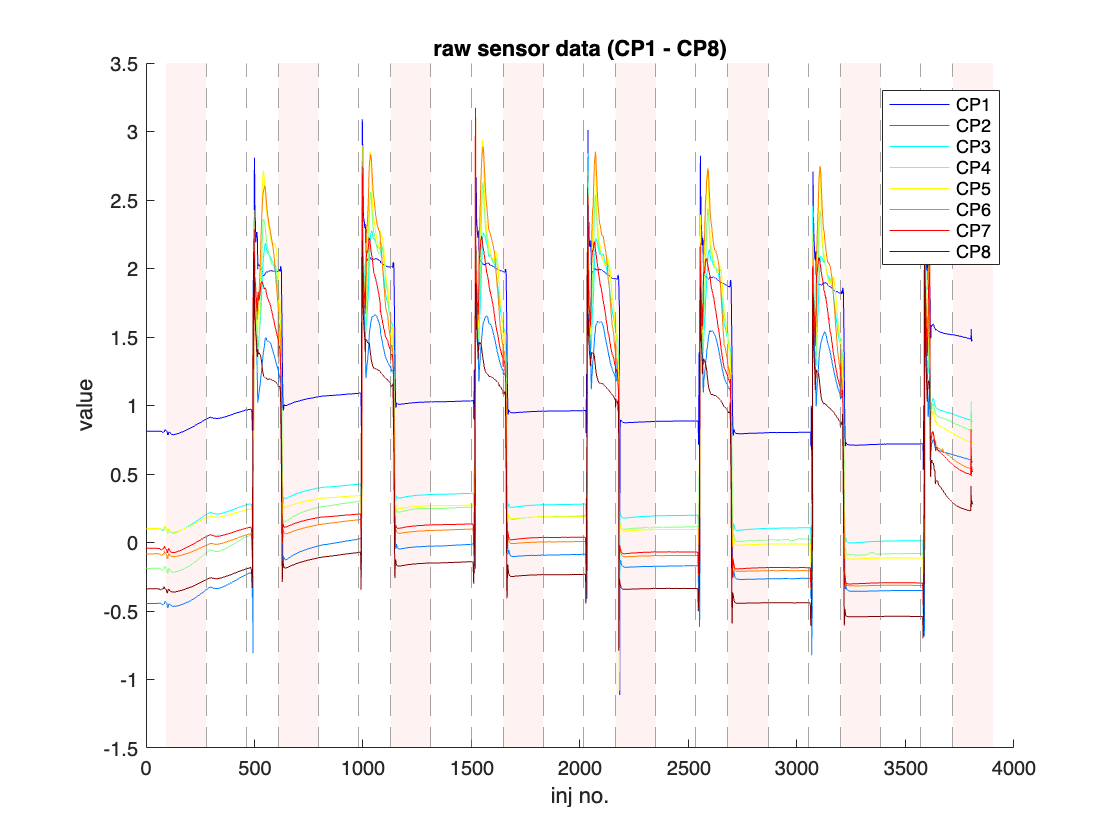

% whats up w/ the other data points in the table?
figure; hold on;
for i = 1:8; plot(data{:, i+26}, Color = colmap(i, :), DisplayName = data.Properties.VariableNames{i+26}); end
xline(find(diff(data.Val_) ~= 0) + 1, '--', Color = [0.5, 0.5, 0.5], HandleVisibility = 'off');
for i = 1:8; xregion(92 + (i-1)*518, 92+(i-1)*518 + 185, FaceColor = 'r', FaceAlpha = 0.05, EdgeColor = 'none', HandleVisibility = 'off'); end
xlabel("inj no."); ylabel("value"); title("raw sensor data (CP1 - CP8)"); legend('show', Interpreter = 'none', Location = 'best');

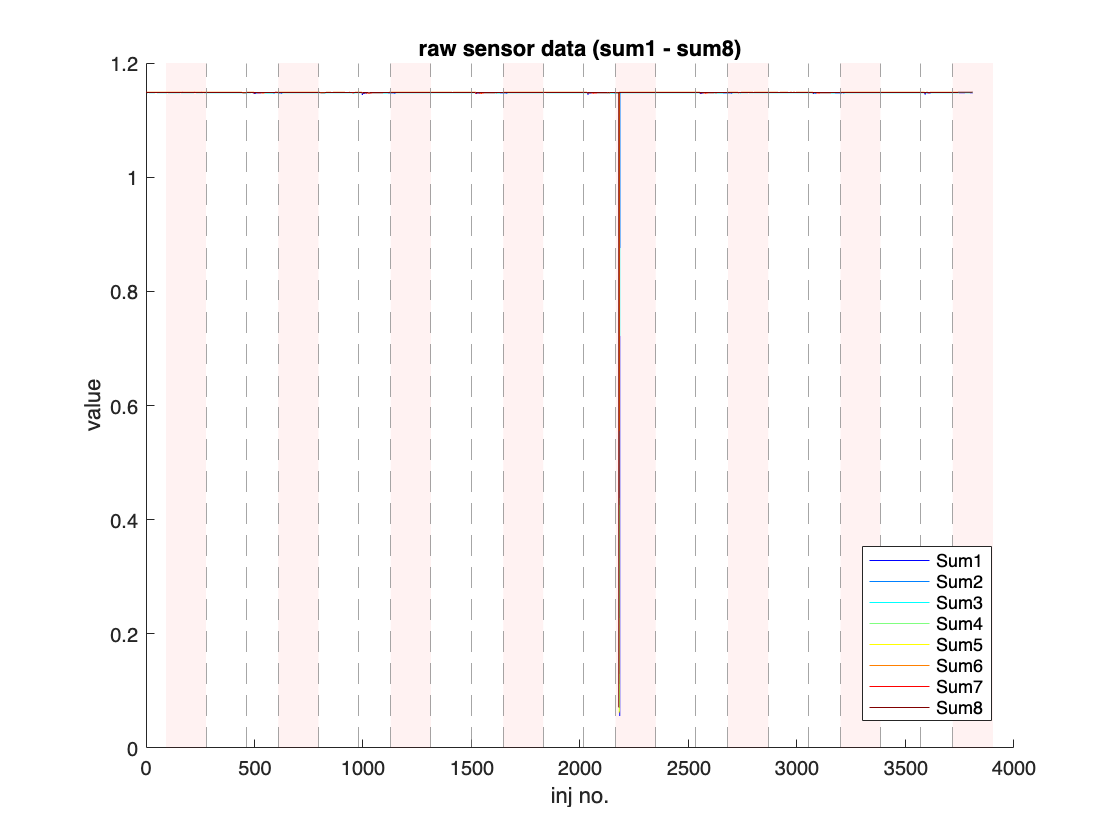

figure; hold on;
for i = 1:8; plot(data{:, i+12}, Color = colmap(i, :), DisplayName = data.Properties.VariableNames{i+12}); end
xline(find(diff(data.Val_) ~= 0) + 1, '--', Color = [0.5, 0.5, 0.5], HandleVisibility = 'off');
for i = 1:8; xregion(92 + (i-1)*518, 92+(i-1)*518 + 185, FaceColor = 'r', FaceAlpha = 0.05, EdgeColor = 'none', HandleVisibility = 'off'); end
xlabel("inj no."); ylabel("value"); title("raw sensor data (sum1 - sum8)"); legend('show', Interpreter = 'none', Location = 'best');

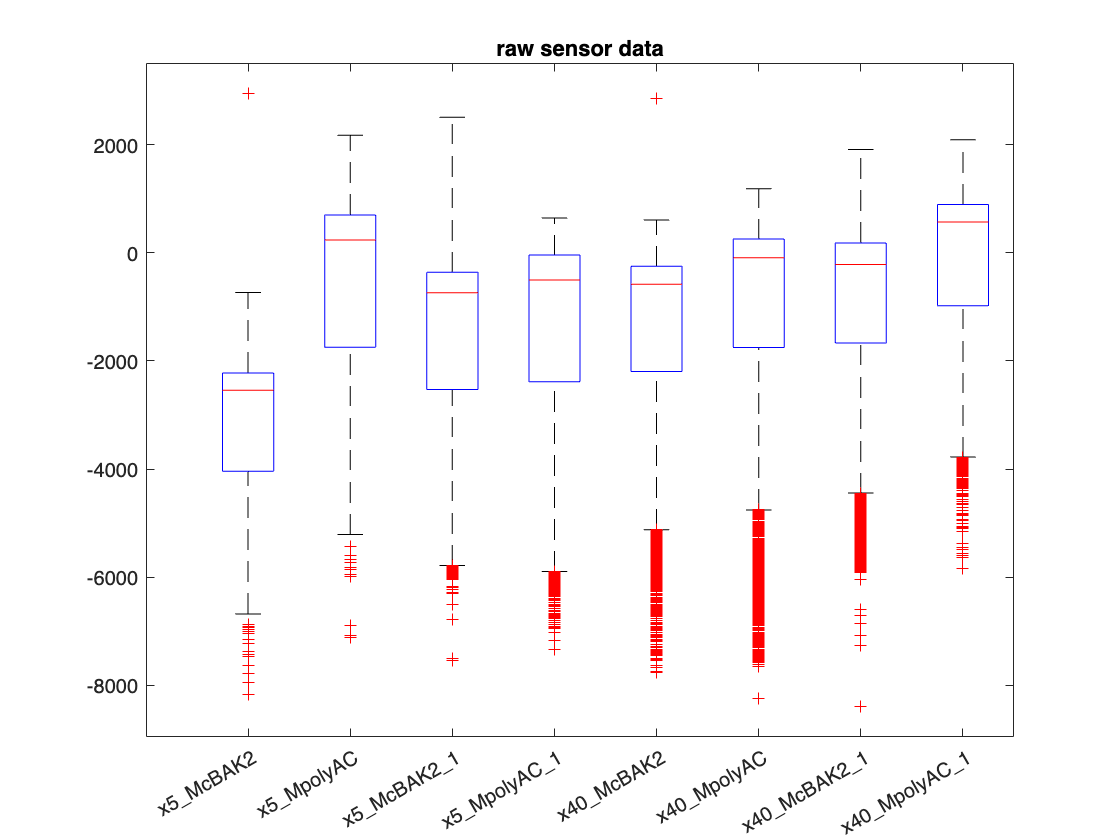

figure; hold on; % analyze variance of each sensor
boxPlotData = []; % initializing
groupingVar = [];
for i = 1:8
    current_label = data.Properties.VariableNames{i+4};
    dataPoints = data.(i+4);
    boxPlotData = [boxPlotData; dataPoints];
    groupingVar = [groupingVar; repmat(i+4, size(dataPoints))];
end
boxplot(boxPlotData, groupingVar, 'Labels', data.Properties.VariableNames(5:12)); title("raw sensor data");

% filter out only relevant val (== 1)
valFiltered_data = data(data.Val_ == 1, :);

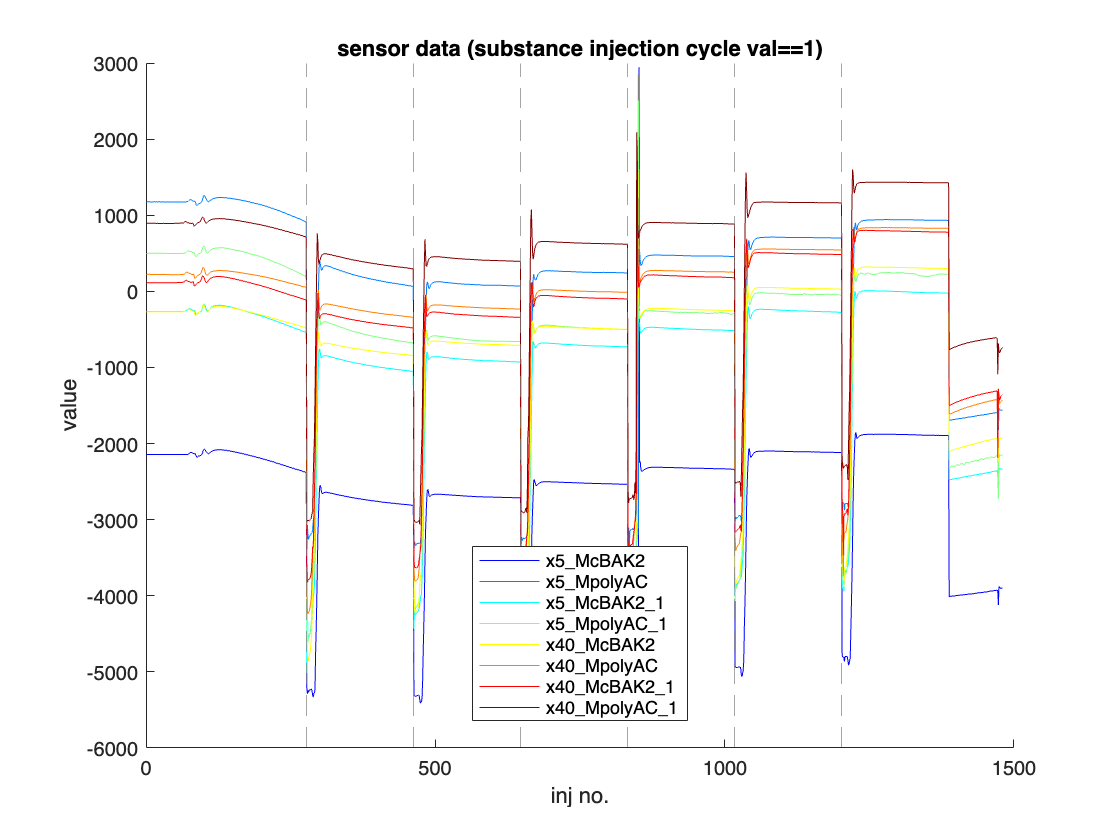

% disp raw data
figure; hold on; % display raw sensor data
for i = 1:8; plot(valFiltered_data{:, i+4}, Color = colmap(i, :), DisplayName = valFiltered_data.Properties.VariableNames{i+4}); end
for i = 1:6; xline(92 + 185*i, '--', 'Color', [0.5, 0.5, 0.5], 'HandleVisibility', 'off'); end
xlabel("inj no."); ylabel("value"); title("sensor data (substance injection cycle val==1)"); legend('show', 'Interpreter', 'none', 'Location', 'best');

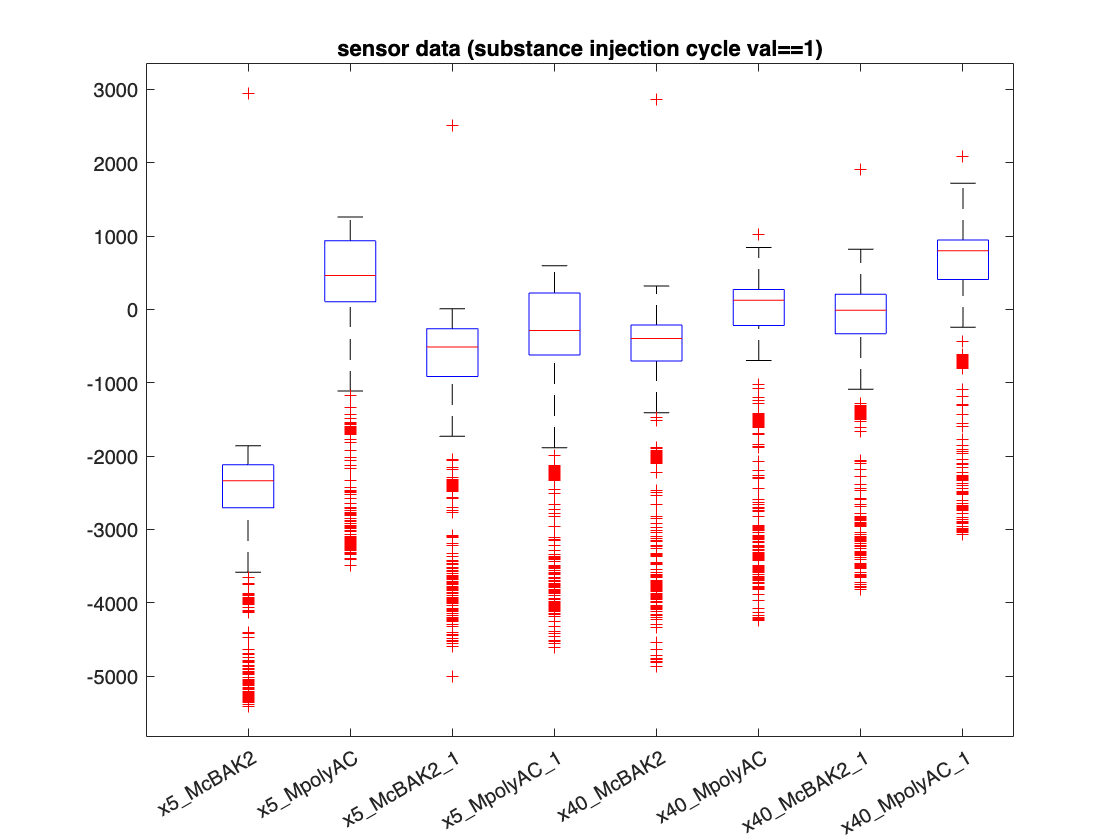

figure; hold on; % analyze variance of each sensor
boxPlotData = []; % initializing
groupingVar = [];
for i = 1:8
    current_label = valFiltered_data.Properties.VariableNames{i+4};
    dataPoints = valFiltered_data.(i+4);
    boxPlotData = [boxPlotData; dataPoints];
    groupingVar = [groupingVar; repmat(i+4, size(dataPoints))];
end
boxplot(boxPlotData, groupingVar, 'Labels', valFiltered_data.Properties.VariableNames(5:12)); title("sensor data (substance injection cycle val==1)");

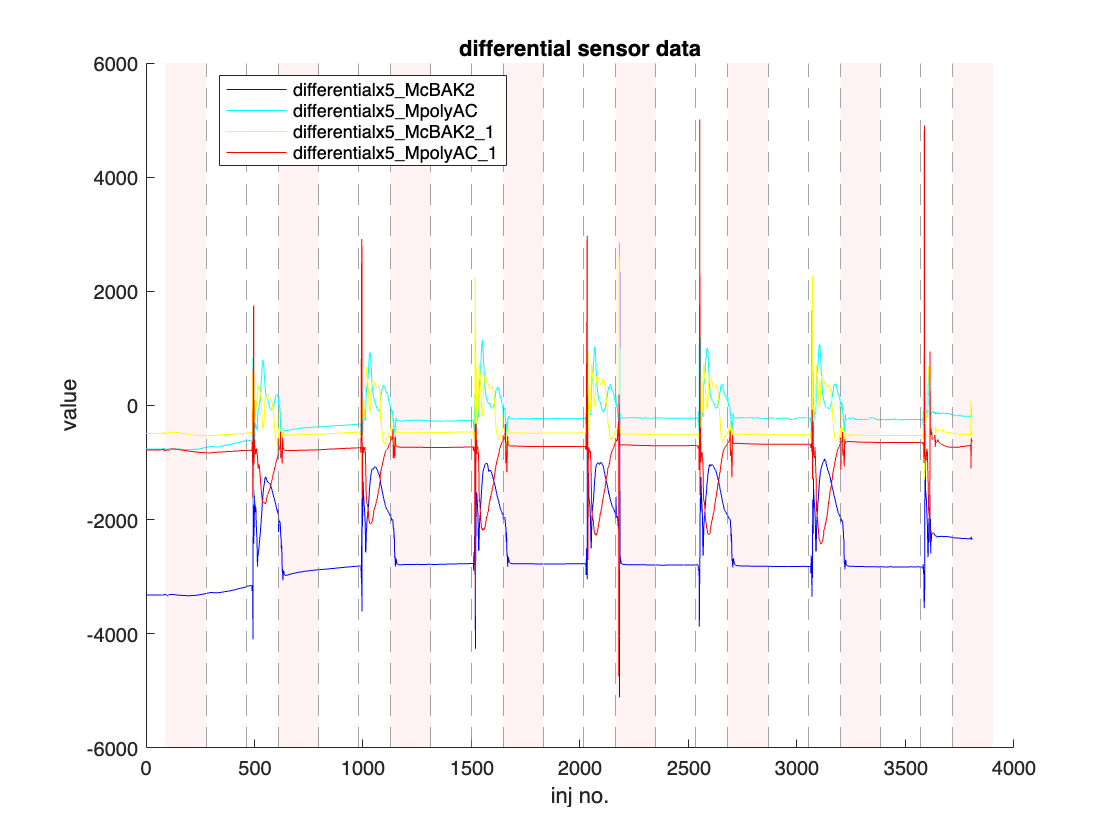

% disp differential data from raw sensor data
figure; hold on;
for i = 1:4; plot(data{:, 2*i+3} - data{:, 2*i+4}, Color = colmap(2*i-1, :), DisplayName = "differential" + data.Properties.VariableNames{i+4}); end
xline(find(diff(data.Val_) ~= 0) + 1, '--', Color = [0.5, 0.5, 0.5], HandleVisibility = 'off');
for i = 1:8; xregion(92 + (i-1)*518, 92+(i-1)*518 + 185, FaceColor = 'r', FaceAlpha = 0.05, EdgeColor = 'none', HandleVisibility = 'off'); end
xlabel("inj no."); ylabel("value"); title("differential sensor data"); legend('show', 'Interpreter', 'none', 'Location', 'best');

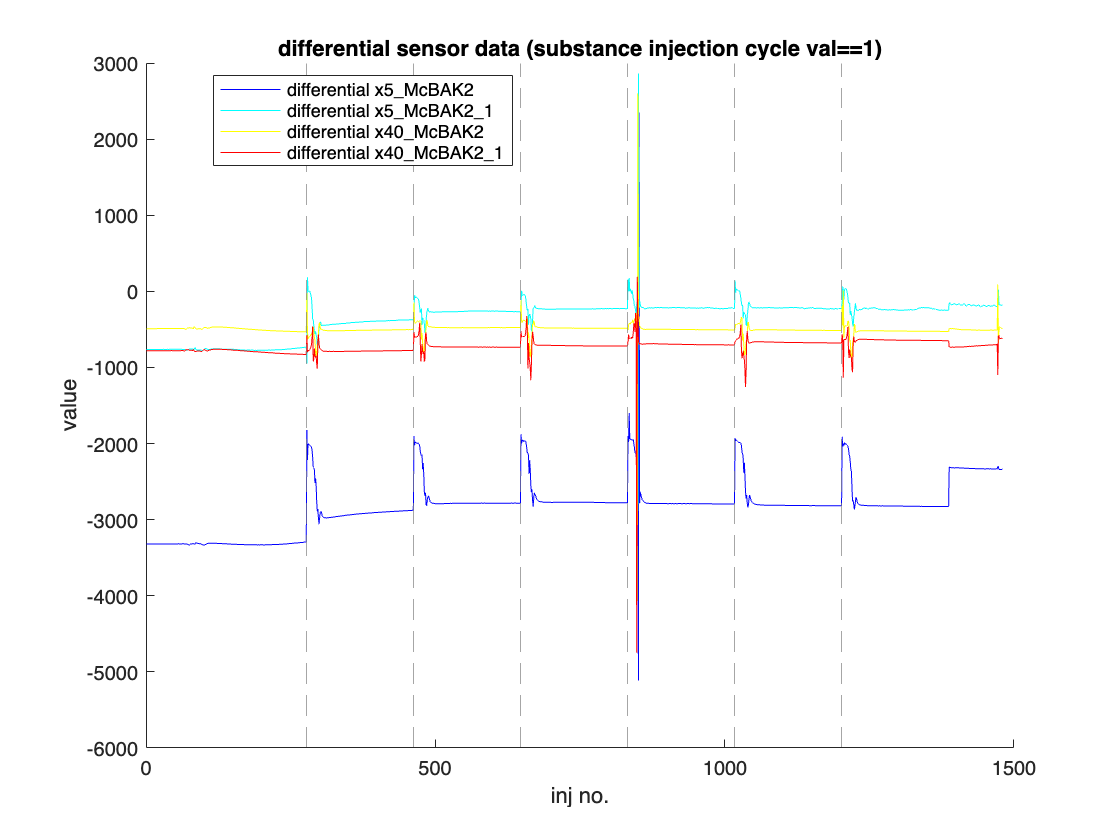

% disp differential data from filtered sensor data for substance injection cycle val==1
figure; hold on; % x5_McBAK2 - x40_MpolyAC_1
plot(valFiltered_data.x5_McBAK2-valFiltered_data.x5_MpolyAC, 'Color', colmap(1, :), 'DisplayName', 'differential x5_McBAK2');
plot(valFiltered_data.x5_McBAK2_1-valFiltered_data.x5_MpolyAC_1, 'Color', colmap(3, :), 'DisplayName', 'differential x5_McBAK2_1');
plot(valFiltered_data.x40_McBAK2-valFiltered_data.x40_MpolyAC, 'Color', colmap(5, :), 'DisplayName', 'differential x40_McBAK2');
plot(valFiltered_data.x40_McBAK2_1-valFiltered_data.x40_MpolyAC_1, 'Color', colmap(7, :), 'DisplayName', 'differential x40_McBAK2_1');
for i = 1:6; xline(92 + 185*i, '--', 'Color', [0.5, 0.5, 0.5], 'HandleVisibility', 'off'); end
xlabel("inj no."); ylabel("value"); title("differential sensor data (substance injection cycle val==1)"); legend('show', 'Interpreter', 'none', 'Location', 'best');

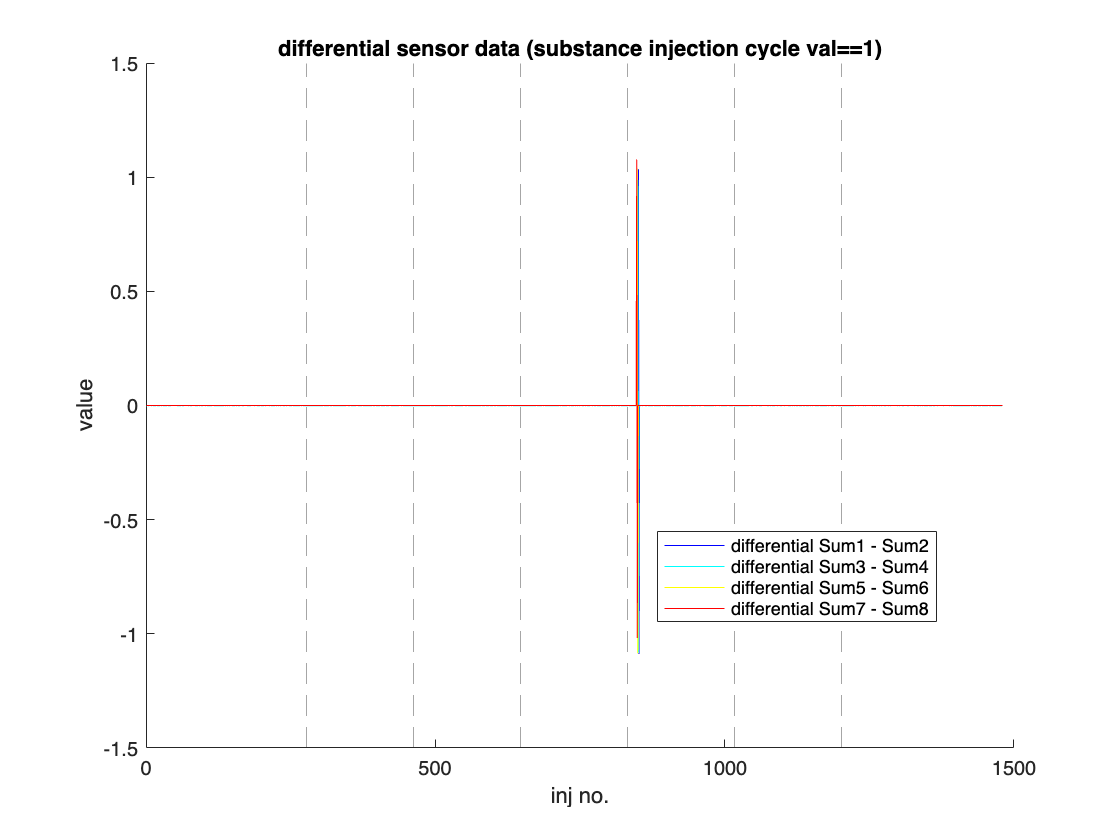

% disp differential data from filtered sensor data for substance injection cycle val==1
figure; hold on; % sum1 - sum8
for i = 1:4; plot(valFiltered_data{:, 2*i+11}-valFiltered_data{:, 2*i+12}, Color = colmap(2*i-1, :), DisplayName = "differential " + valFiltered_data.Properties.VariableNames{2*i+11} + " - " + valFiltered_data.Properties.VariableNames{2*i+12}); end
for i = 1:6; xline(92 + 185*i, '--', 'Color', [0.5, 0.5, 0.5], 'HandleVisibility', 'off'); end
xlabel("inj no."); ylabel("value"); title("differential sensor data (substance injection cycle val==1)"); legend('show', 'Interpreter', 'none', 'Location', 'best');

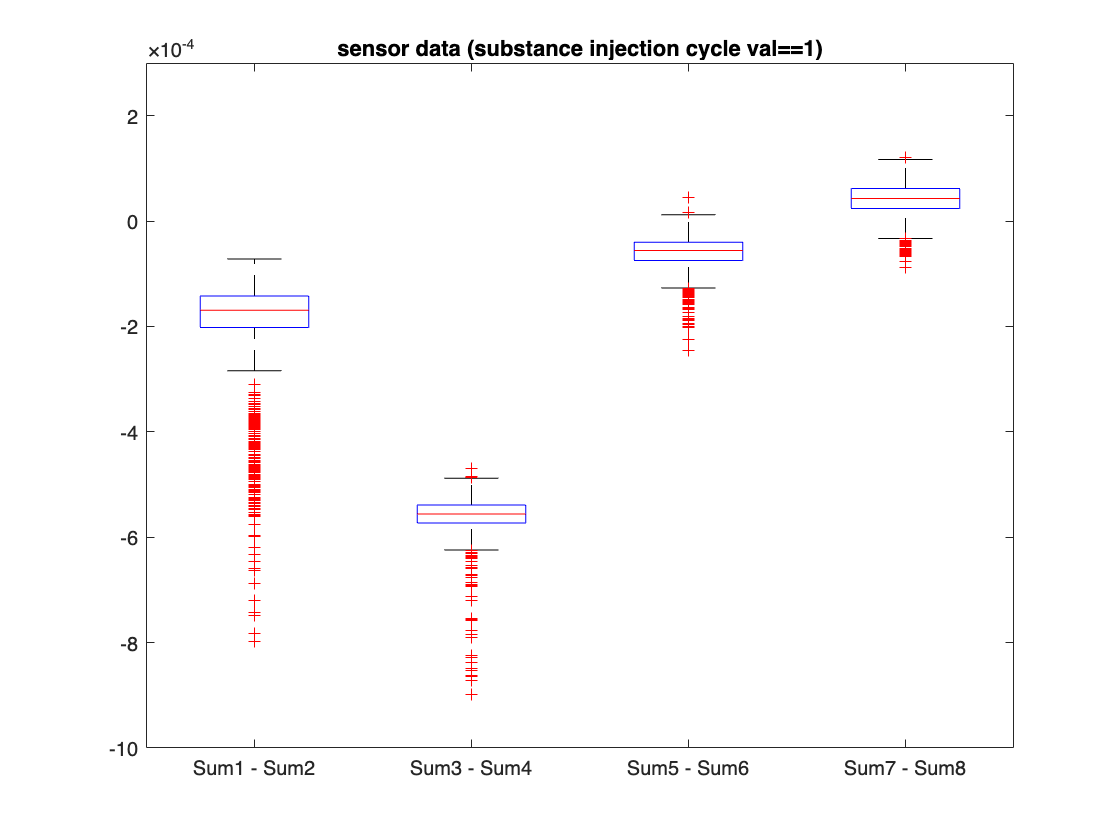

figure; hold on; % analyze variance of sum1 - sum8 differentials
boxPlotData = []; % initializing
groupingVar = [];
labelArray = [];
for i = 1:4
    current_label = char(valFiltered_data.Properties.VariableNames{2*i+11} + " - " + valFiltered_data.Properties.VariableNames{2*i+12});
    dataPoints = valFiltered_data{:, 2*i+11}-valFiltered_data{:, 2*i+12};
    boxPlotData = [boxPlotData; dataPoints];
    groupingVar = [groupingVar; repmat(2*i+11, size(dataPoints))];
    labelArray = [labelArray; current_label];
end
boxplot(boxPlotData, groupingVar, Labels = labelArray); title("sensor data (substance injection cycle val==1)");
xlim([0.5 4.5]);ylim([-0.001 0.0003]);

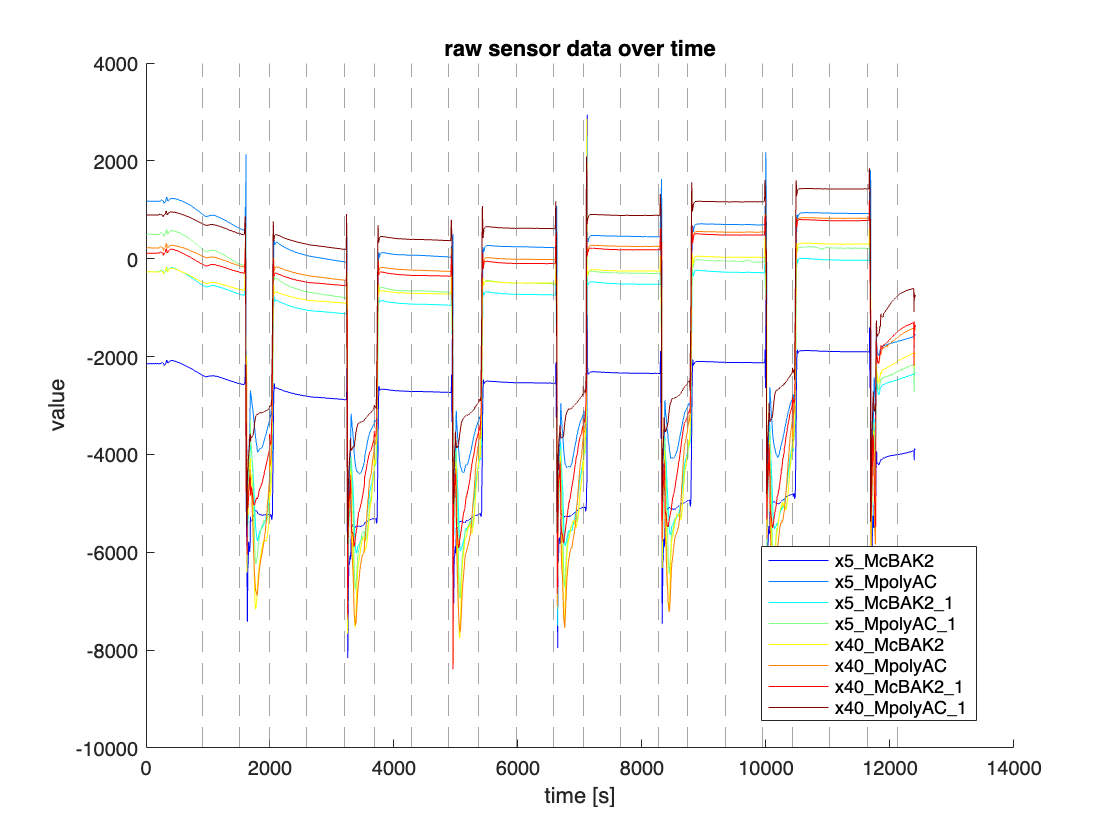

% display raw data over time
figure; hold on;
for i = 1:8; plot(data{:, "T_s_"}, data{:, i+4}, Color = colmap(i, :), DisplayName = data.Properties.VariableNames{i+4}); end
xline(data.T_s_(find(diff(data.Val_) ~= 0) + 1), '--', Color = [0.5, 0.5, 0.5], HandleVisibility = 'off');
%for i = 1:8; xregion(92 + (i-1)*518, 92+(i-1)*518 + 185, FaceColor = 'r', FaceAlpha = 0.05, EdgeColor = 'none', HandleVisibility = 'off'); end
xlabel("time [s]"); ylabel("value"); title("raw sensor data over time"); legend('show', Interpreter = 'none', Location = 'best');

% A %% time filtered data %% 60 sec after Val_==3 and 120 after Val_==1
srtIdx = find(diff([0; data.Val_ == 3; 0]) == 1); % find starting and ending of all Val_ == 3 sections (co(nh2)2 injections)
endIdx = find(diff([0; data.Val_ == 3; 0]) == -1) - 1;

% calc sections to remove
remove_mask = false(height(data), 1); % mask for filter % 1 if to remove
for k = 1:length(srtIdx); start_time = data.T_s_(srtIdx(k)); end_time = data.T_s_(endIdx(k)) + 120;  % start time / end time (+120sec)
    remove_mask = remove_mask | (data.T_s_ >= start_time & data.T_s_ <= end_time); end

timeFiltered_data = data(~remove_mask, :);

% B %% "new" time filter: only injection
timeFiltered_data = data(data.Val_ == 2, :);

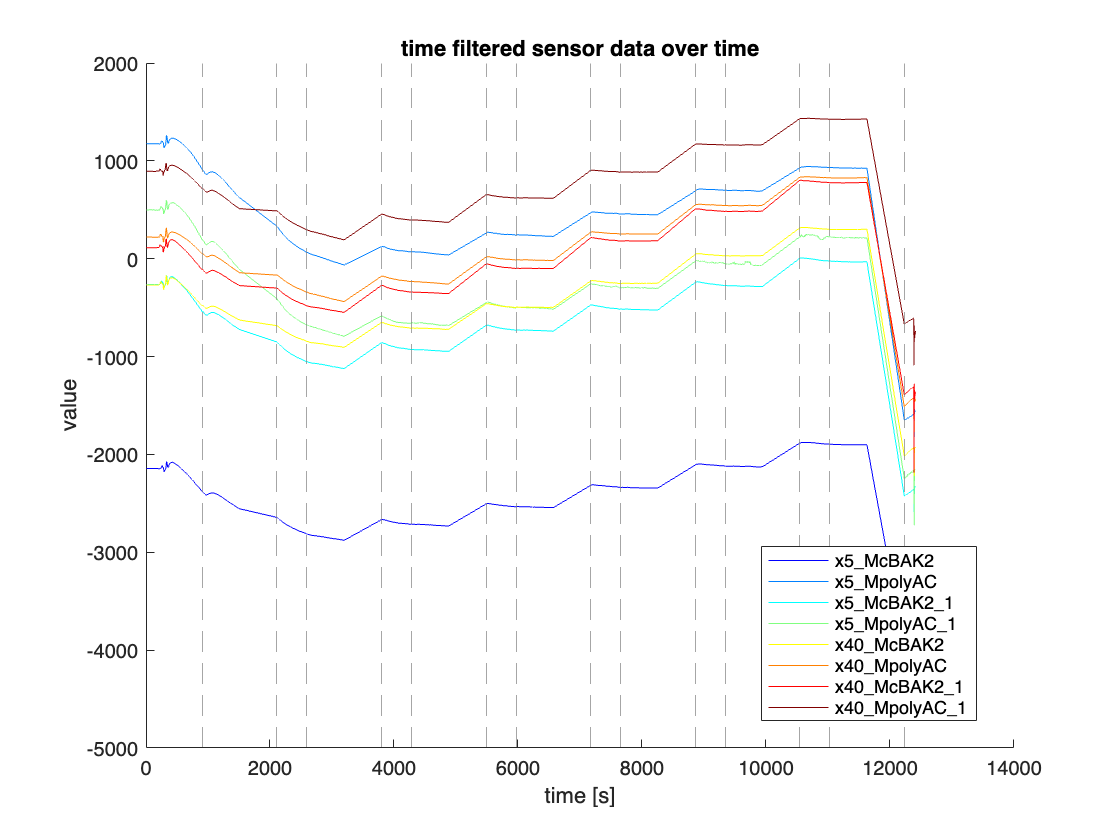

% display time filtered data over time
figure; hold on;
for i = 1:8; plot(timeFiltered_data{:, "T_s_"}, timeFiltered_data{:, i+4}, Color = colmap(i, :), DisplayName = timeFiltered_data.Properties.VariableNames{i+4}); end
xline(timeFiltered_data.T_s_(find(diff(timeFiltered_data.Val_) ~= 0) + 1), '--', Color = [0.5, 0.5, 0.5], HandleVisibility = 'off');
%for i = 1:8; xregion(92 + (i-1)*518, 92+(i-1)*518 + 185, FaceColor = 'r', FaceAlpha = 0.05, EdgeColor = 'none', HandleVisibility = 'off'); end
xlabel("time [s]"); ylabel("value"); title("time filtered sensor data over time"); legend('show', Interpreter = 'none', Location = 'best');

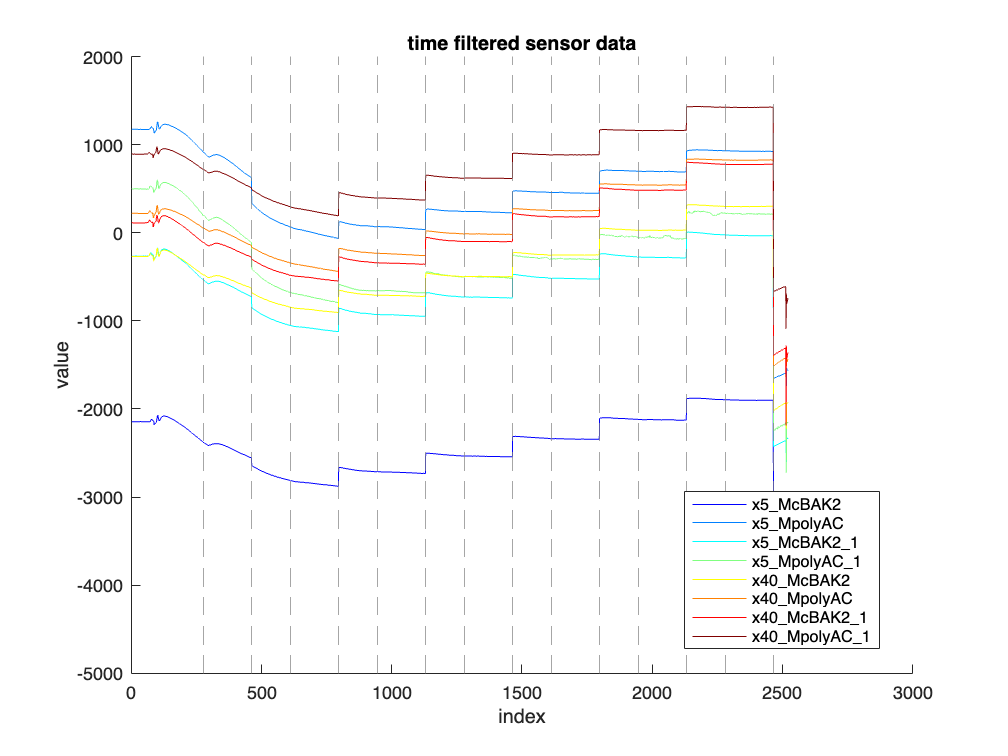

% display time filtered data
figure; hold on;
for i = 1:8; plot(timeFiltered_data{:, i+4}, Color = colmap(i, :), DisplayName = timeFiltered_data.Properties.VariableNames{i+4}); end
xline(find(diff(timeFiltered_data.Val_) ~= 0) + 1, '--', Color = [0.5, 0.5, 0.5], HandleVisibility = 'off');
%for i = 1:8; xregion(92 + (i-1)*518, 92+(i-1)*518 + 185, FaceColor = 'r', FaceAlpha = 0.05, EdgeColor = 'none', HandleVisibility = 'off'); end
xlabel("index"); ylabel("value"); title("time filtered sensor data"); legend('show', Interpreter = 'none', Location = 'best');

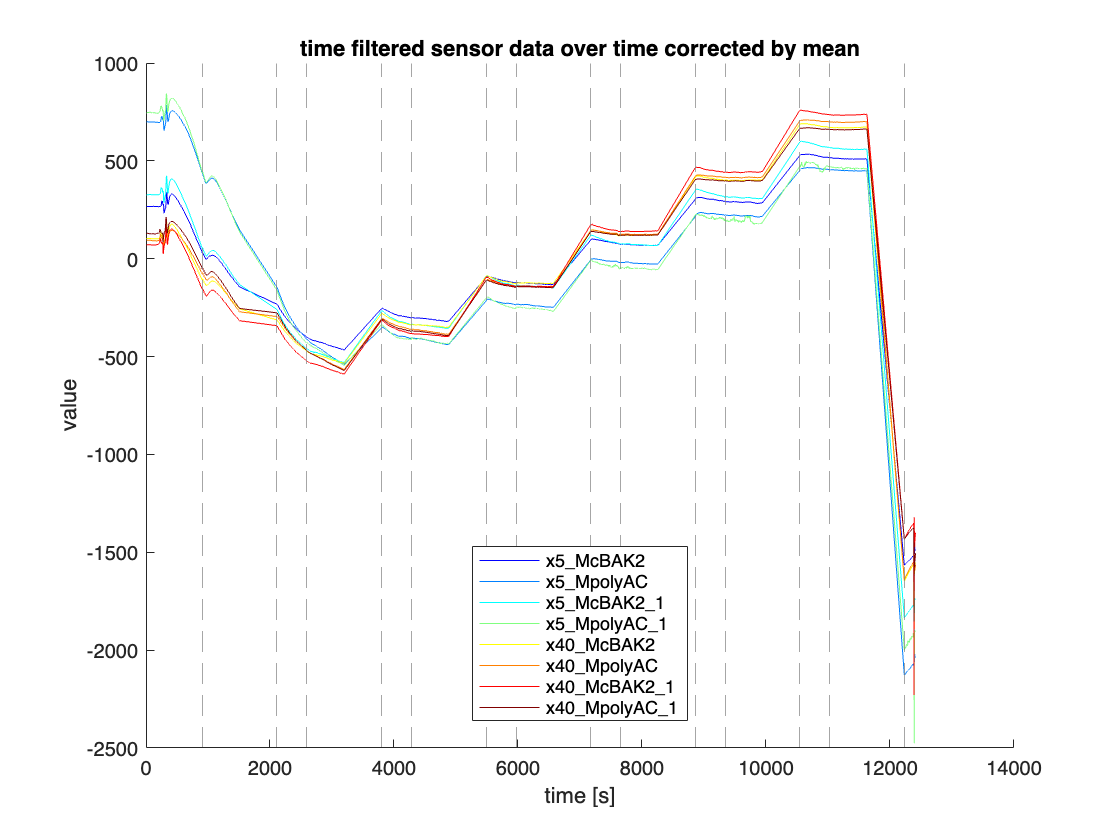

% mean value "drift" correction
figure; hold on;
for i = 1:8
    sensDataMean = mean(timeFiltered_data{:, i+4}); % get mean 
    plot(timeFiltered_data{:, "T_s_"}, timeFiltered_data{:, i+4} - sensDataMean, Color = colmap(i, :), DisplayName = timeFiltered_data.Properties.VariableNames{i+4}); 
end
xline(timeFiltered_data.T_s_(find(diff(timeFiltered_data.Val_) ~= 0) + 1), '--', Color = [0.5, 0.5, 0.5], HandleVisibility = 'off');
%for i = 1:8; xregion(92 + (i-1)*518, 92+(i-1)*518 + 185, FaceColor = 'r', FaceAlpha = 0.05, EdgeColor = 'none', HandleVisibility = 'off'); end
xlabel("time [s]"); ylabel("value"); title("time filtered sensor data over time corrected by mean"); legend('show', Interpreter = 'none', Location = 'best');

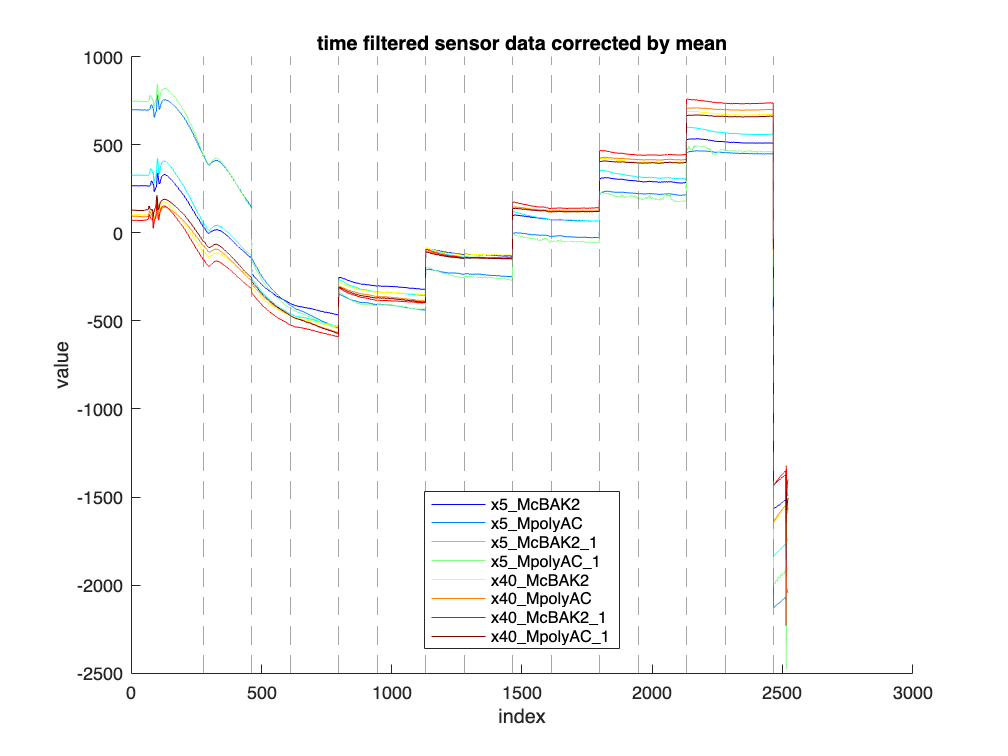

figure; hold on;
for i = 1:8
    sensDataMean = mean(timeFiltered_data{:, i+4}); % get mean 
    plot(timeFiltered_data{:, i+4} - sensDataMean, Color = colmap(i, :), DisplayName = timeFiltered_data.Properties.VariableNames{i+4}); 
end
xline(find(diff(timeFiltered_data.Val_) ~= 0) + 1, '--', Color = [0.5, 0.5, 0.5], HandleVisibility = 'off');
%for i = 1:8; xregion(92 + (i-1)*518, 92+(i-1)*518 + 185, FaceColor = 'r', FaceAlpha = 0.05, EdgeColor = 'none', HandleVisibility = 'off'); end
xlabel("index"); ylabel("value"); title("time filtered sensor data corrected by mean"); legend('show', Interpreter = 'none', Location = 'best');

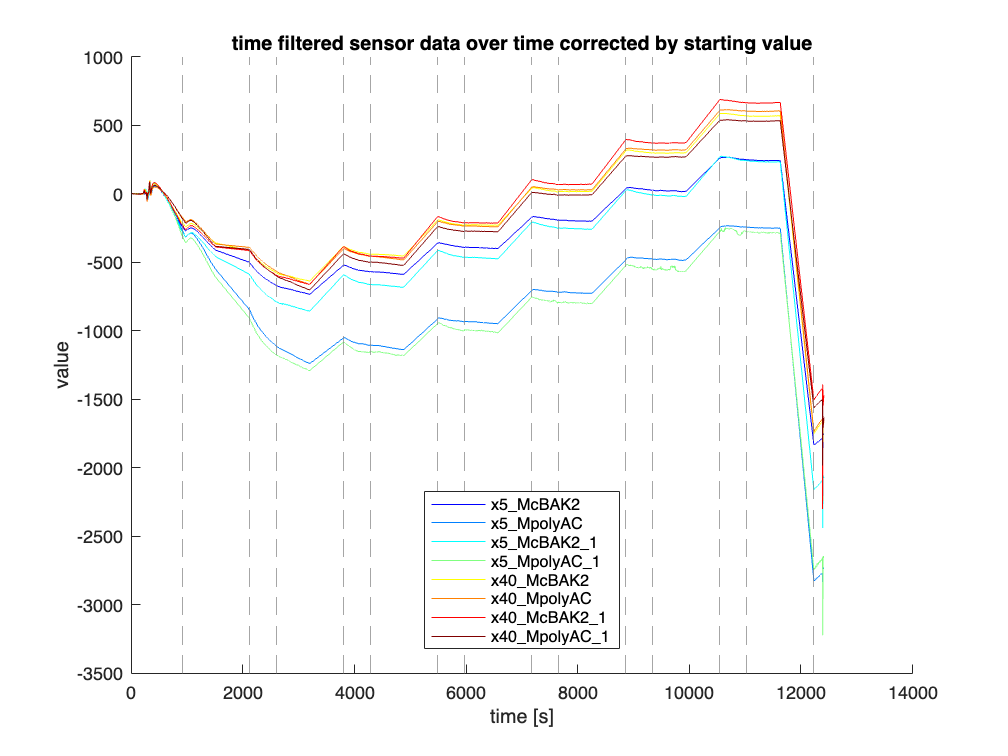

% starting value to 0
figure; hold on;
for i = 1:8
    sensDataMean = mean(timeFiltered_data{:, i+4}); % get mean 
    sensDataSrtVal = timeFiltered_data{1, i+4} - sensDataMean; % get start value 
    plot(timeFiltered_data{:, "T_s_"}, timeFiltered_data{:, i+4} - sensDataMean - sensDataSrtVal, Color = colmap(i, :), DisplayName = timeFiltered_data.Properties.VariableNames{i+4}); 
end
xline(timeFiltered_data.T_s_(find(diff(timeFiltered_data.Val_) ~= 0) + 1), '--', Color = [0.5, 0.5, 0.5], HandleVisibility = 'off');
%for i = 1:8; xregion(92 + (i-1)*518, 92+(i-1)*518 + 185, FaceColor = 'r', FaceAlpha = 0.05, EdgeColor = 'none', HandleVisibility = 'off'); end
xlabel("time [s]"); ylabel("value"); title("time filtered sensor data over time corrected by starting value"); legend('show', Interpreter = 'none', Location = 'best');

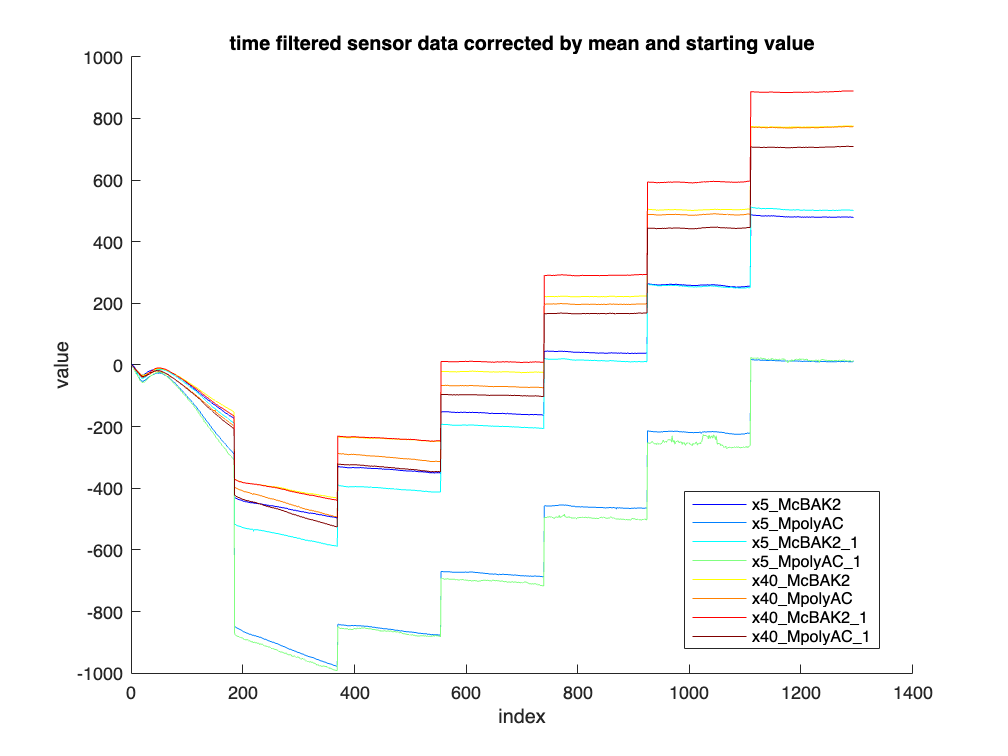

figure; hold on;
for i = 1:8
    sensDataMean = mean(timeFiltered_data{:, i+4}); % get mean 
    sensDataSrtVal = timeFiltered_data{1, i+4} - sensDataMean; % get start value 
    plot(timeFiltered_data{:, i+4} - sensDataMean - sensDataSrtVal, Color = colmap(i, :), DisplayName = timeFiltered_data.Properties.VariableNames{i+4}); 
end
%xline(find(diff(timeFiltered_data.Val_) ~= 0) + 1, '--', Color = [0.5, 0.5, 0.5], HandleVisibility = 'off');
%for i = 1:8; xregion(92 + (i-1)*518, 92+(i-1)*518 + 185, FaceColor = 'r', FaceAlpha = 0.05, EdgeColor = 'none', HandleVisibility = 'off'); end
xlabel("index"); ylabel("value"); title("time filtered sensor data corrected by mean and starting value"); legend('show', Interpreter = 'none', Location = 'best');

corr_analysis_data = timeFiltered_data;
for i = 1:8
    sensDataMean = mean(corr_analysis_data{:, i+4}); % get mean 
    sensDataSrtVal = corr_analysis_data{1, i+4} - sensDataMean; % get start value 
    corr_analysis_data{:, i+4} = corr_analysis_data{:, i+4} - sensDataMean - sensDataSrtVal;
end
relevant_sensor_labels = timeFiltered_data.Properties.VariableNames(5:12);
corr_analysis_data = corr_analysis_data{:, 5:12};

% mse %% 0 = equal
MSE = squareform(pdist(corr_analysis_data', 'euclidean').^2);
disp(MSE);

   1.0e+08 *

         0    2.6734    0.0271    2.8962    0.3887    0.3162    0.7035    0.1951
    2.6734         0    2.3380    0.0069    4.8935    4.4580    5.7492    3.9246
    0.0271    2.3380         0    2.5447    0.4760    0.3648    0.7931    0.2241
    2.8962    0.0069    2.5447         0    5.1875    4.7370    6.0648    4.1891
    0.3887    4.8935    0.4760    5.1875         0    0.0173    0.0494    0.0586
    0.3162    4.4580    0.3648    4.7370    0.0173         0    0.0840    0.0180
    0.7035    5.7492    0.7931    6.0648    0.0494    0.0840         0    0.1775
    0.1951    3.9246    0.2241    4.1891    0.0586    0.0180    0.1775         0



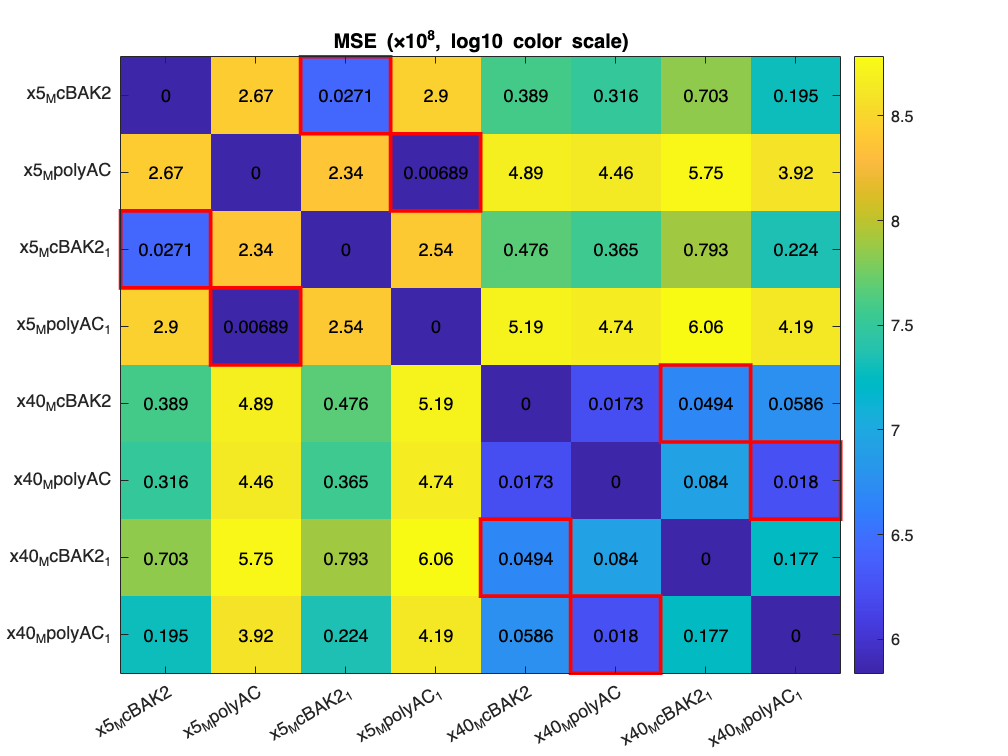

MSE_scaled10e8 = MSE / ( 10 ^ 8); % floor( log10( max( abs( MSE(:) ) ) ) )
figure; imagesc(log10(MSE)); colorbar; colormap('parula'); % surf(MSE); hold on;
title(sprintf("MSE (×10^{%d}, log10 color scale)", 8)); xticks(1:8); yticks(1:8); xticklabels(relevant_sensor_labels); yticklabels(relevant_sensor_labels);
[nRows, nCols] = size(MSE); % add values
arrayfun(@(i, j) text(j, i, sprintf('%.3g', MSE_scaled10e8(i, j)), FontSize = 10, HorizontalAlignment = 'center', Color = 'k'), repelem(1:nRows, nCols), repmat(1:nCols, 1, nRows));
highlight_positions = [5,7; 7,5; 6,8; 8,6; 9,11; 11,9; 10,12; 12,10] - 4; % highlight relevant positions
arrayfun(@(k) rectangle(Position = [highlight_positions(k,2)-0.5, highlight_positions(k,1)-0.5, 1, 1], EdgeColor = 'r', LineWidth = 2), 1:size(highlight_positions, 1));

% cross correlation %% 1 = equal, 0 = totally different
CrossCorr = corr(corr_analysis_data);
disp(CrossCorr);

    1.0000    0.8891    0.9994    0.8835    0.9900    0.9924    0.9859    0.9953
    0.8891    1.0000    0.9017    0.9991    0.8168    0.8287    0.8015    0.8431
    0.9994    0.9017    1.0000    0.8963    0.9852    0.9880    0.9802    0.9917
    0.8835    0.9991    0.8963    1.0000    0.8100    0.8218    0.7940    0.8360
    0.9900    0.8168    0.9852    0.8100    1.0000    0.9996    0.9996    0.9985
    0.9924    0.8287    0.9880    0.8218    0.9996    1.0000    0.9988    0.9995
    0.9859    0.8015    0.9802    0.7940    0.9996    0.9988    1.0000    0.9972
    0.9953    0.8431    0.9917    0.8360    0.9985    0.9995    0.9972    1.0000



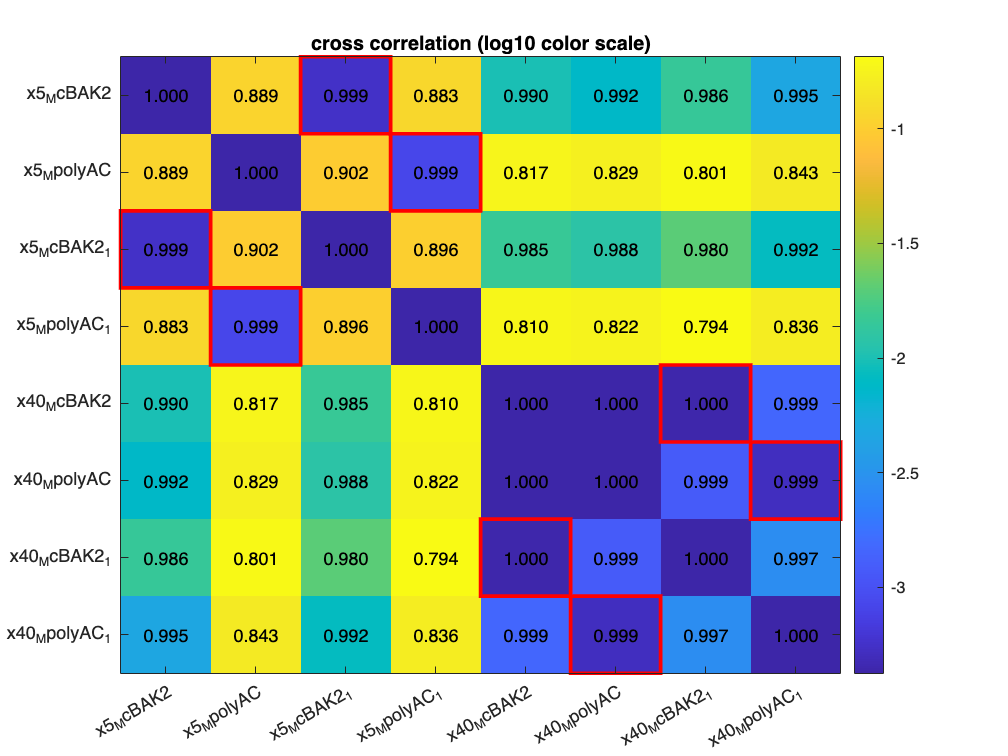

figure; imagesc(log10(-CrossCorr+1)); colorbar; colormap('parula'); title("cross correlation (log10 color scale)"); % surf(CrossCorr); hold on;
xticks(1:8); yticks(1:8); xticklabels(relevant_sensor_labels); yticklabels(relevant_sensor_labels);
[nRows, nCols] = size(CrossCorr); % add values
arrayfun(@(i, j) text(j, i, sprintf('%.3f', CrossCorr(i,j)), FontSize = 10, HorizontalAlignment = 'center', Color = 'k'), repelem(1:nRows, nCols), repmat(1:nCols, 1, nRows));
highlight_positions = [5,7; 7,5; 6,8; 8,6; 9,11; 11,9; 10,12; 12,10] - 4; % highlight relevant positions
arrayfun(@(k) rectangle(Position = [highlight_positions(k,2)-0.5, highlight_positions(k,1)-0.5, 1, 1], EdgeColor = 'r', LineWidth = 2), 1:size(highlight_positions, 1));

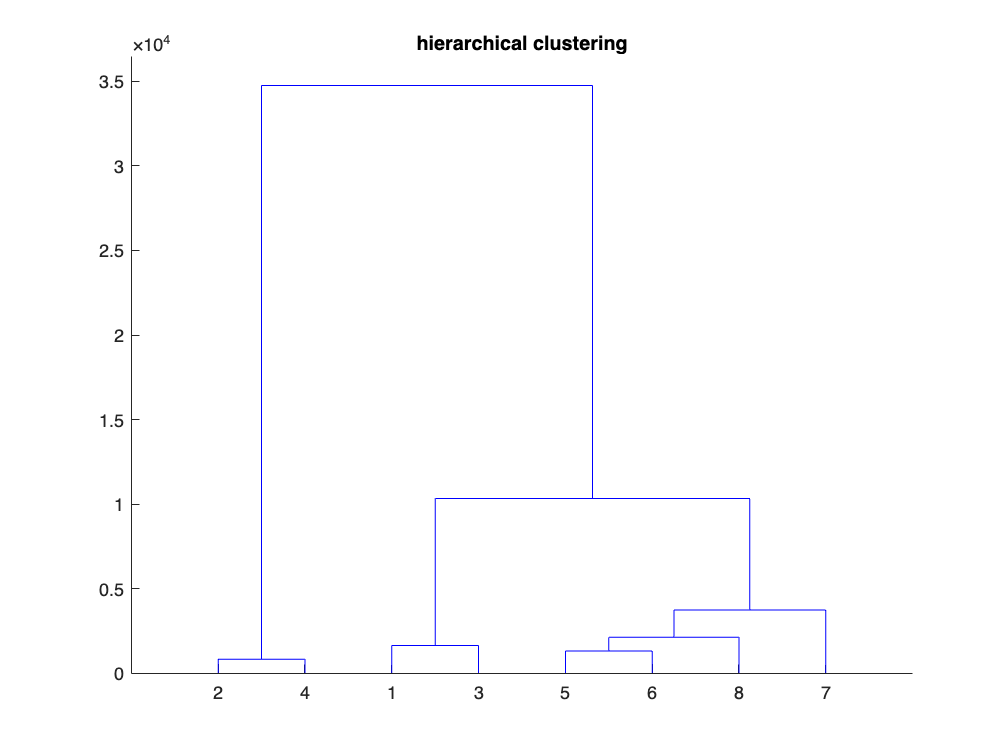

% cluster analysis
Z = linkage(corr_analysis_data', 'ward');
dendrogram(Z);
title("hierarchical clustering");

% pca analysis
[coeff, score] = pca(corr_analysis_data');

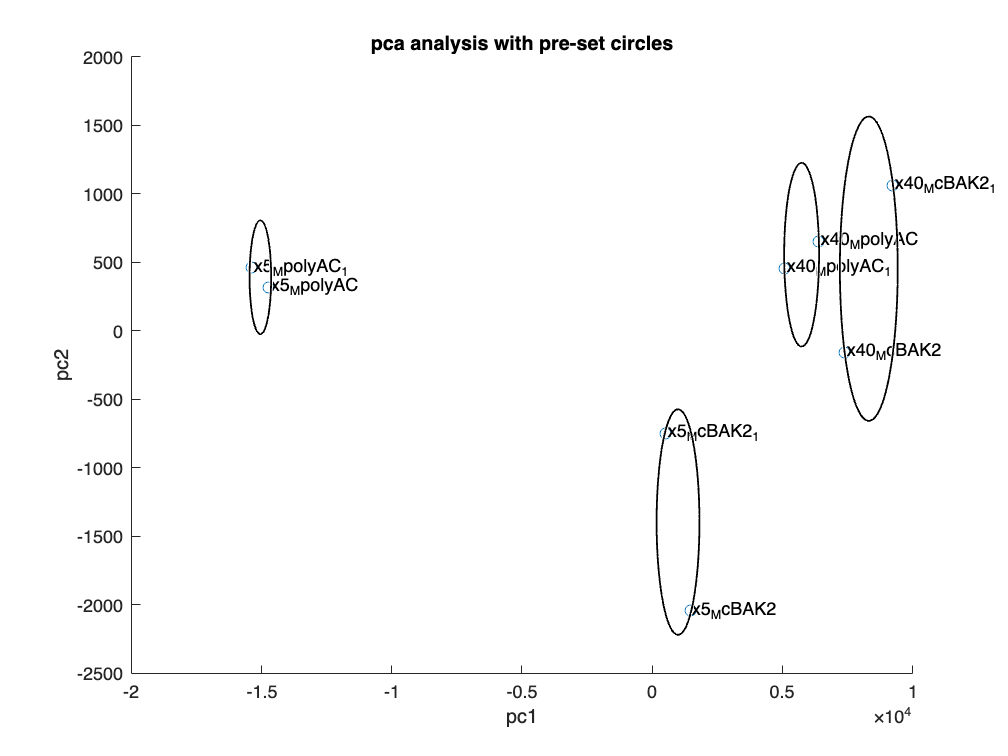

figure;
scatter(score(:,1), score(:,2));
text(score(:,1), score(:,2), relevant_sensor_labels); % num2str((5:12)')r
title("pca analysis with pre-set circles");
xlabel("pc1");
ylabel("pc2");
hold on;
cluster_pairs = {[1,3], [2,4], [5,7], [6,8]};
for k = 1:length(cluster_pairs)
    rows = cluster_pairs{k};
    center = mean(score(rows, :), 1); % center
    radius = max(vecnorm(score(rows, :) - center, 2, 2)); % radius
    viscircles([center(1), center(2)], radius, 'EdgeColor', 'k', 'LineWidth', 1);
end
hold off;

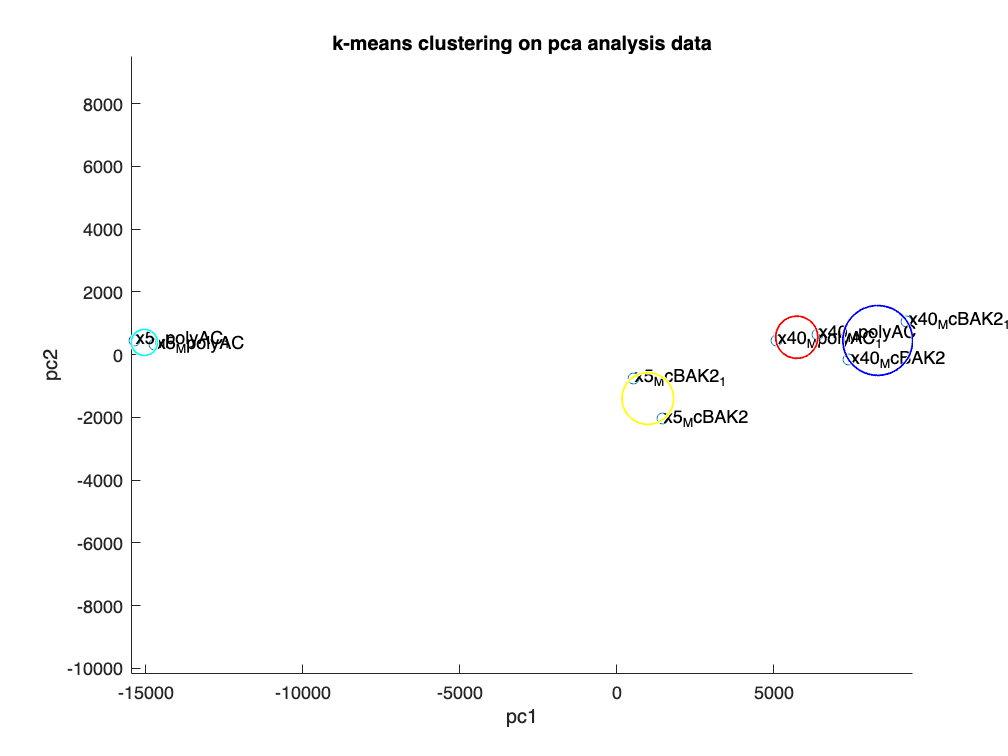

% k-means clustering over pca
k = 4;
[idx, C] = kmeans(score(:, 1:2), k); % k-means clustering

figure;
scatter(score(:,1), score(:,2));
text(score(:,1), score(:,2), relevant_sensor_labels); % num2str((5:12)')r
title("k-means clustering on pca analysis data");
xlabel("pc1");
ylabel("pc2");
hold on;
axis equal;
cluster_pairs = arrayfun(@(c) find(idx == c), unique(idx), UniformOutput = false);
for i = 1:length(cluster_pairs)
    rows = cluster_pairs{i};
    center = mean(score(rows, :), 1); % center
    radius = max(vecnorm(score(rows, :) - center, 2, 2)); % radius
    circle_col = colmap(2*i-1, :);
    viscircles([center(1), center(2)], radius, EdgeColor = circle_col, LineWidth = 1);
end
hold off;

% tsne
A_tsne2 = tsne(corr_analysis_data'); %%% Warning: The loss value is negative. The solution may not have converged correctly. Tune the LearnRate parameter for better convergence

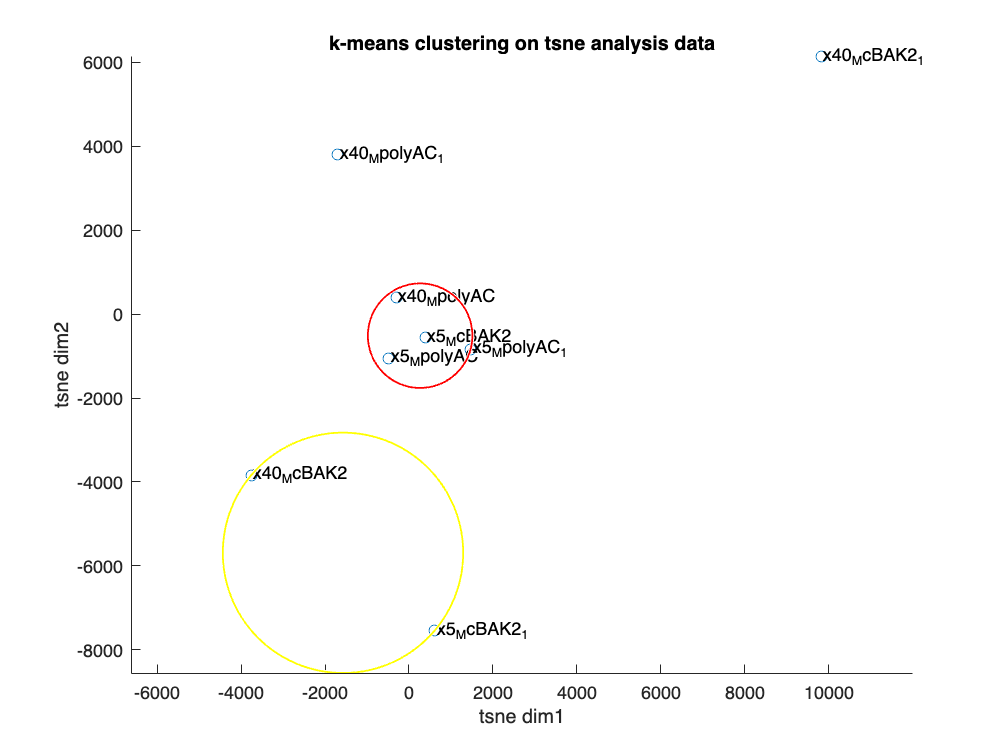

% k-means clustering over tsne
k = 4;
[idx, C] = kmeans(A_tsne2(:, 1:2), k); % k-means clustering

figure;
scatter(A_tsne2(:,1), A_tsne2(:,2));
text(A_tsne2(:,1), A_tsne2(:,2), relevant_sensor_labels); % num2str((5:12)')r
title("k-means clustering on tsne analysis data");
xlabel("tsne dim1");
ylabel("tsne dim2");
hold on;
axis equal;
cluster_pairs = arrayfun(@(c) find(idx == c), unique(idx), UniformOutput = false);
for i = 1:length(cluster_pairs)
    rows = cluster_pairs{i};
    center = mean(A_tsne2(rows, :), 1); % center
    radius = max(vecnorm(A_tsne2(rows, :) - center, 2, 2)); % radius
    circle_col = colmap(2*i-1, :);
    viscircles([center(1), center(2)], radius, EdgeColor = circle_col, LineWidth = 1);
end
hold off;

% split in cycles
timeFiltered_data_split = timeFiltered_data;
timeFiltered_data_split.cycle = zeros(size(timeFiltered_data_split.Inj_));  % Initialisiere mit NaN für die durch 3 teilbaren Werte

cycle = 1;
timeFiltered_data_split.cycle(1) = cycle;
for i = 2:length(timeFiltered_data_split.Inj_)
    if timeFiltered_data_split.Inj_(i) - timeFiltered_data_split.Inj_(i-1) > 1
        cycle = cycle + 1;
    end
    timeFiltered_data_split.cycle(i) = cycle;
end

unique_cycles = unique(timeFiltered_data_split.cycle);
num_cycles = numel(unique_cycles);
num_sensors = 8;

% how long are these cycles (no. measurements and time)
cycle_length_tbl = table(Size = [num_cycles, 3], VariableTypes = {'double', 'double', 'double'}, VariableNames = {'cycle', 'no_measurements', 'time'});
for i = 1:num_cycles
    cycleIdx = unique_cycles(i);
    cycleData = timeFiltered_data_split(timeFiltered_data_split.cycle == cycleIdx, :);
  
    cycle_length_tbl.cycle(i) = cycleIdx;
    cycle_length_tbl.no_measurements(i) = height(cycleData);
    cycle_length_tbl.time(i) = max(cycleData.T_s_) - min(cycleData.T_s_);
end
disp(cycle_length_tbl)

    cycle    no_measurements     time 
    _____    _______________    ______

      1            184          596.89
      2            185          599.81
      3            185          598.82
      4            185          598.78
      5            185          598.83
      6            185          598.78
      7            185          598.82



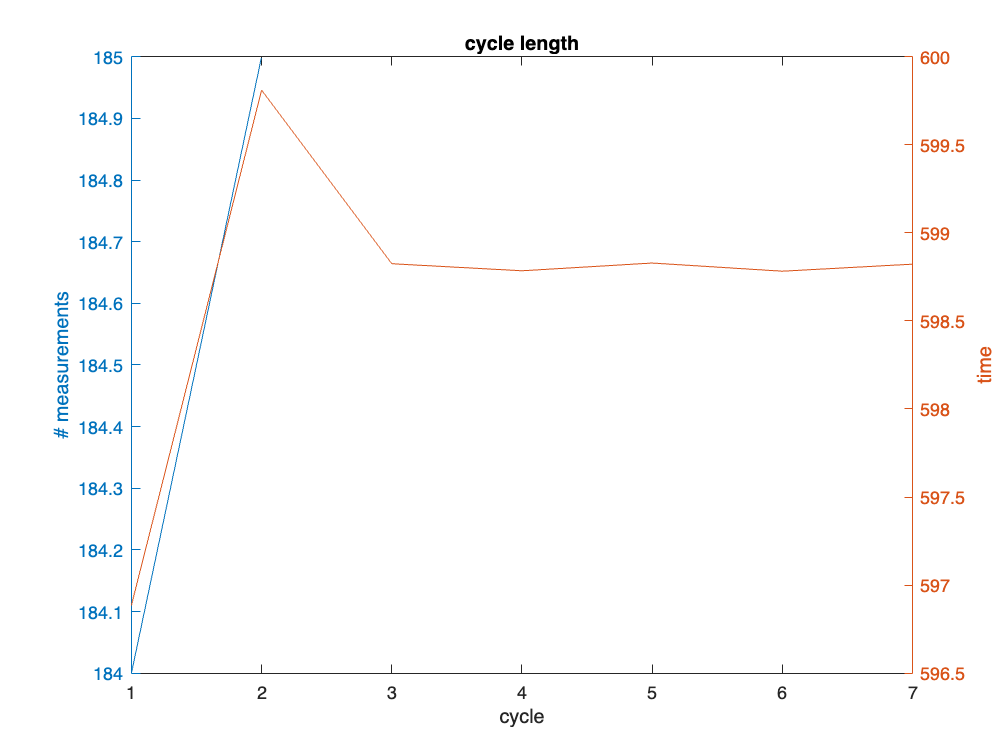

figure; yyaxis left; plot(cycle_length_tbl.no_measurements); ylabel("# measurements");
hold on; yyaxis right; plot(cycle_length_tbl.time); title("cycle length"); xlabel("cycle"); ylabel("time"); hold off;

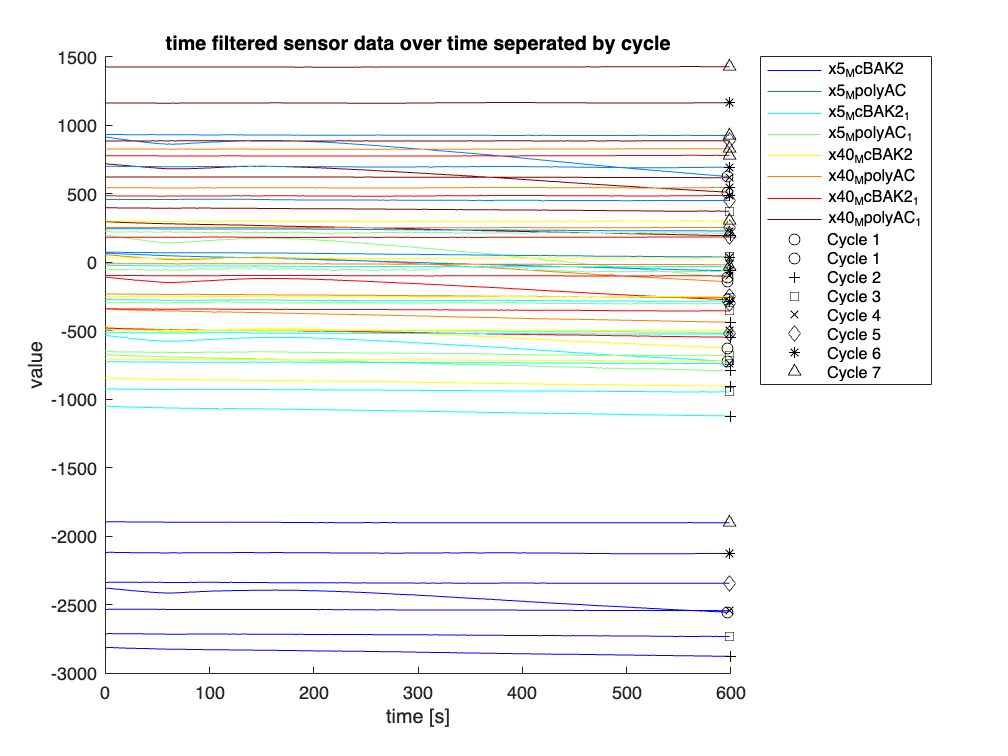

% plot cycle split data
cyclemarker = {'o', '+', 'square', 'x', 'diamond', '*', '^', '|', '>', '<', 'v', 'hexagram', '.'};

h_sensors = []; % handles for plot
legend_labels_sensors = {}; % legend labels sensors (different colors)
h_cycles = []; % handles for markers
legend_labels_cycles = {}; % legend labels cycles (different markers)

figure; hold on;
for i = 1:num_cycles % loop over cycles
    cycleIdx = unique_cycles(i);
    cycleData = timeFiltered_data_split(timeFiltered_data_split.cycle == i, :);
    init_time = cycleData.T_s_(1);
    cycleData.T_s_ = cycleData.T_s_ - init_time; % reset init time

    for j = 1:num_sensors % loop over sensors
        h_sensor = plot(cycleData.T_s_, cycleData{:, j+4}, Color = colmap(j, :));  % each sensor same color %% cycleData{:, "T_s_"}, ...
        h_sensors(end+1) = h_sensor;
        legend_labels_sensors{end+1} = timeFiltered_data_split.Properties.VariableNames{j+4};

        h_cycle = scatter(cycle_length_tbl.time(i), cycleData{end, j+4}, MarkerEdgeColor = 'k', Marker = cyclemarker(i)); % each cycle same marker at the end
        h_cycles(end+1) = h_cycle;
        legend_labels_cycles{end+1} = "Cycle " + cycleIdx;
    end
end
h_sensors = h_sensors(1:8); legend_labels_sensors = legend_labels_sensors(1:8); % delete double legend entries
h_cycles = h_cycles(mod(1:length(h_cycles), num_cycles) == 1); legend_labels_cycles = legend_labels_cycles(mod(1:length(legend_labels_cycles), num_cycles) == 1);
xlabel("time [s]"); ylabel("value"); title("time filtered sensor data over time seperated by cycle"); legend([h_sensors, h_cycles], [legend_labels_sensors, legend_labels_cycles], Location = 'bestoutside'); hold off;

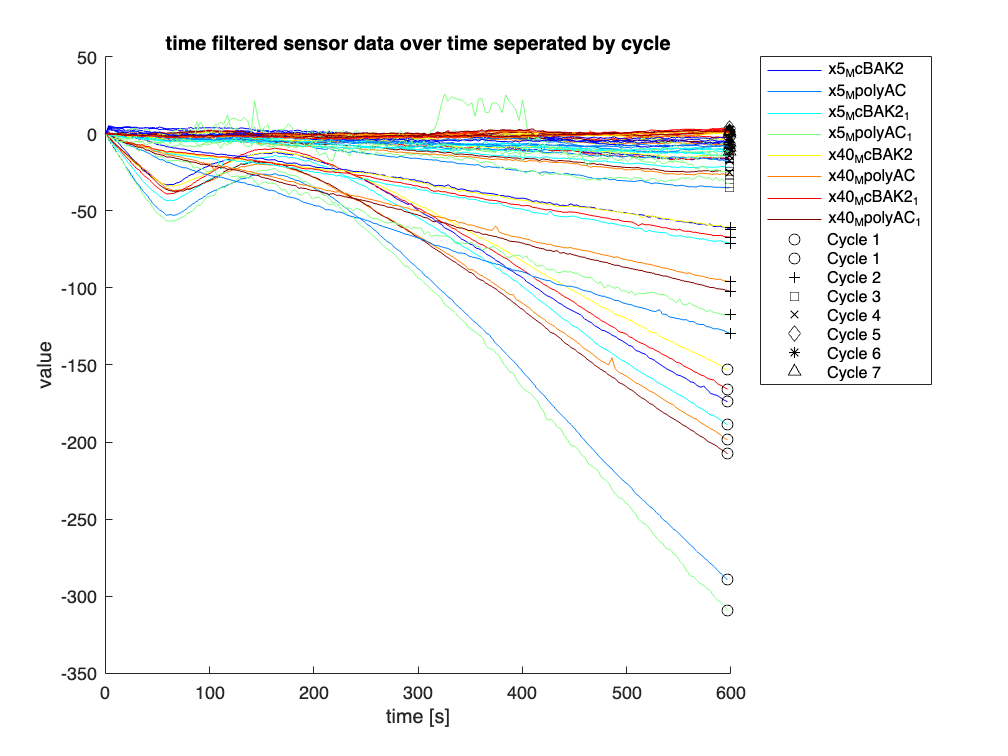

% plot cycle split data corrected by by mean and starting value
cyclemarker = {'o', '+', 'square', 'x', 'diamond', '*', '^', '|', '>', '<', 'v', 'hexagram', '.'};

h_sensors = []; % handles for plot
legend_labels_sensors = {}; % legend labels sensors (different colors)
h_cycles = []; % handles for markers
legend_labels_cycles = {}; % legend labels cycles (different markers)

figure; hold on;
for i = 1:num_cycles % loop over cycles
    cycleIdx = unique_cycles(i);
    cycleData = timeFiltered_data_split(timeFiltered_data_split.cycle == i, :);
    init_time = cycleData.T_s_(1);
    cycleData.T_s_ = cycleData.T_s_ - init_time; % reset init time

    for j = 1:num_sensors % loop over sensors
        sensDataMean = mean(cycleData{:, j+4}); % get mean 
        sensDataSrtVal = cycleData{1, j+4} - sensDataMean; % get start value 

        h_sensor = plot(cycleData.T_s_, cycleData{:, j+4} - sensDataMean - sensDataSrtVal, Color = colmap(j, :));  % each sensor same color %% cycleData{:, "T_s_"}, ...
        h_sensors(end+1) = h_sensor;
        legend_labels_sensors{end+1} = timeFiltered_data_split.Properties.VariableNames{j+4};

        h_cycle = scatter(cycle_length_tbl.time(i), cycleData{end, j+4} - sensDataMean - sensDataSrtVal, MarkerEdgeColor = 'k', Marker = cyclemarker(i)); % each cycle same marker at the end
        h_cycles(end+1) = h_cycle;
        legend_labels_cycles{end+1} = "Cycle " + cycleIdx;
    end
end
h_sensors = h_sensors(1:8); legend_labels_sensors = legend_labels_sensors(1:8); % delete double legend entries
h_cycles = h_cycles(mod(1:length(h_cycles), num_cycles) == 1); legend_labels_cycles = legend_labels_cycles(mod(1:length(legend_labels_cycles), num_cycles) == 1);
xlabel("time [s]"); ylabel("value"); title("time filtered sensor data over time seperated by cycle"); legend([h_sensors, h_cycles], [legend_labels_sensors, legend_labels_cycles], Location = 'bestoutside'); hold off;

%% (A)
%num_cycles_ns = num_cycles-2; % "normal" size cycles (namely 2-8)
%corr_analysis_data_split = array2table(zeros(num_cycles_ns*num_sensors,
%334)); % 334 = # measurements per cycle and sensor 

%% for (B)
num_cycles_ns = num_cycles-1;
corr_analysis_data_split = array2table(zeros(num_cycles_ns*num_sensors, 185)); % 

cycleMasks = cell(num_cycles_ns, 1); % precomputing cycle mask
for c = 1:num_cycles_ns; cycleMasks{c} = (timeFiltered_data_split.cycle == c+1); end


for s = 1:num_sensors % over sensors
    sensorData = table2array(timeFiltered_data_split(:, s+4));
    for c = 1:num_cycles_ns % over cycles
        rowIdx = (s - 1) * num_cycles_ns + c;
        mask = cycleMasks{c};
        sensorDataInCycle = sensorData(mask);  

        dataMean = mean(sensorDataInCycle); % get mean 
        dataSrtVal = sensorDataInCycle(1) - sensDataMean; % get start value 
        sensorDataInCycle = sensorDataInCycle - dataMean - dataSrtVal;

        corr_analysis_data_split{rowIdx, :} = sensorDataInCycle';
    end
end

corr_analysis_data_split = table2array(corr_analysis_data_split);

% mse %% 0 = equal
MSE = squareform(pdist(corr_analysis_data_split, 'euclidean').^2);
disp(MSE);

   1.0e+09 *

         0    0.0019    0.0144    0.0418    0.0896    0.1561    1.5362    1.5442    1.7330    1.9830    2.2883    2.6000    0.5759    0.6614    0.8077    0.9805    1.1970    1.4437    0.8481    0.8672    0.9984    1.1744    1.4129    1.7095    0.7190    0.8229    0.9973    1.2167    1.5003    1.7966    1.1321    1.2355    1.4555    1.7422    2.0883    2.4555    1.0089    1.1344    1.3668    1.6618    2.0150    2.3891    1.7908    1.9096    2.1873    2.5340    2.9285    3.3285
    0.0019         0    0.0059    0.0259    0.0655    0.1237    1.4308    1.4384    1.6207    1.8628    2.1590    2.4620    0.5120    0.5928    0.7317    0.8965    1.1040    1.3414    0.7702    0.7883    0.9136    1.0823    1.3117    1.5980    0.6473    0.7461    0.9125    1.1229    1.3959    1.6822    1.0419    1.1410    1.3527    1.6296    1.9648    2.3215    0.9237    1.0439    1.2673    1.5519    1.8938    2.2569    1.6767    1.7916    2.0609    2.3978    2.7820    3.1721
    0.0144    0.0059    

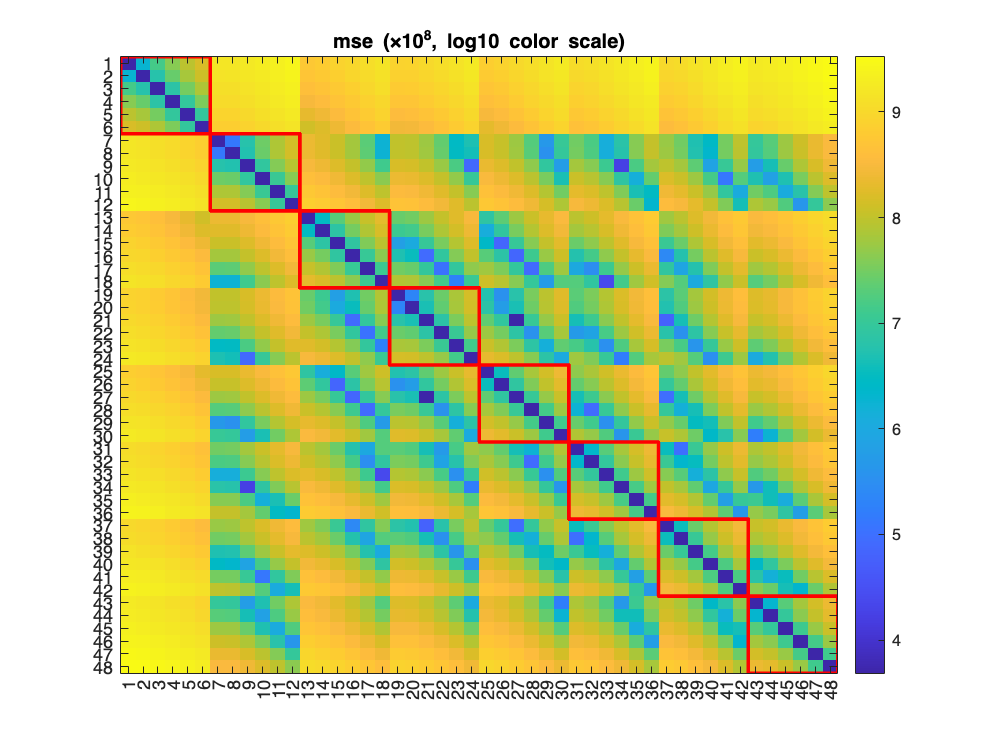

MSE_scaled10e8 = MSE / (10 ^ 8); % floor( log10( max( abs( MSE(:) ) ) ) )
figure; imagesc(log10(MSE)); colorbar; colormap('parula'); % surf(MSE); hold on;
title(sprintf("mse (×10^{%d}, log10 color scale)", 8)); xticks(1:48); yticks(1:48); xticklabels(1:48); yticklabels(1:48);
[nRows, nCols] = size(MSE); % add values
hold on; arrayfun(@(idx) plot([idx-0.5, idx+5.5, idx+5.5, idx-0.5, idx-0.5], [idx-0.5, idx-0.5, idx+5.5, idx+5.5, idx-0.5], 'r', 'LineWidth', 2), 1:6:48); hold off; % highlight same sensor data

%arrayfun(@(i, j) text(j, i, sprintf('%.3g', MSE_scaled10e8(i, j)), FontSize = 10, HorizontalAlignment = 'center', Color = 'k'), repelem(1:nRows, nCols), repmat(1:nCols, 1, nRows));

We can lightly see, that data in the red boxes (same sensor) has a slightly lower mse, still there is a lot of outlier points, etc. etc.

% CrossCorr
CrossCorrPearson = corr(corr_analysis_data_split', Type = 'Pearson');
disp(CrossCorrPearson);

    1.0000    0.9871    0.9776    0.9232    0.8378    0.8434    0.9993    0.9911    0.9831    0.9071    0.7922    0.9239    0.9987    0.9877    0.9814    0.9645    0.9127    0.8610    0.9981    0.9592    0.9338    0.7810    0.3875    0.7003    0.9991    0.9764    0.7913   -0.3355   -0.4040   -0.6146    0.9991    0.9934    0.9690    0.3481   -0.2676   -0.5665    0.9987    0.9849    0.7462   -0.4752   -0.5443   -0.6842    0.9992    0.9904    0.9526   -0.2454   -0.4526   -0.6519
    0.9871    1.0000    0.9764    0.8938    0.8655    0.7761    0.9865    0.9950    0.9858    0.8912    0.8230    0.8671    0.9907    0.9959    0.9860    0.9529    0.9032    0.7928    0.9853    0.9749    0.9340    0.8058    0.4440    0.6489    0.9891    0.9894    0.8087   -0.3704   -0.4516   -0.6937    0.9864    0.9936    0.9716    0.2888   -0.2634   -0.6597    0.9910    0.9927    0.7557   -0.5320   -0.5389   -0.7620    0.9874    0.9952    0.9619   -0.2789   -0.4362   -0.7289
    0.9776    0.9764    1.0000    0.91

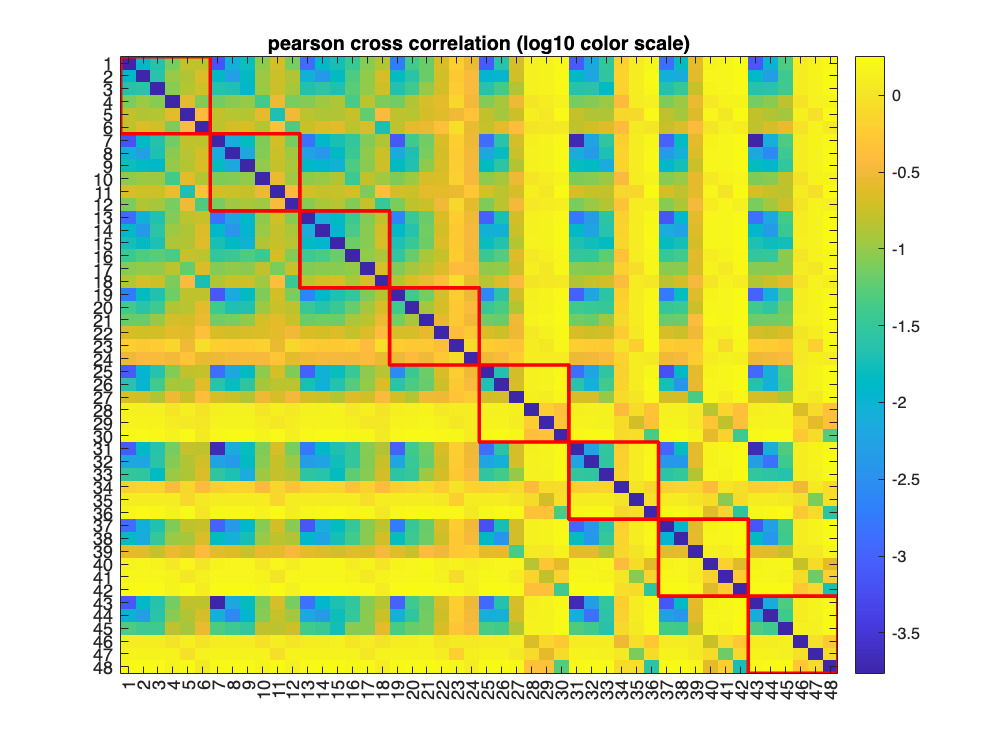

figure; imagesc(log10(-CrossCorrPearson+1)); colorbar; colormap('parula'); title("pearson cross correlation (log10 color scale)"); % surf(CrossCorrPearson); hold on;
xticks(1:48); yticks(1:48); xticklabels(1:48); yticklabels(1:48)
[nRows, nCols] = size(CrossCorrPearson); % add values
hold on; arrayfun(@(idx) plot([idx-0.5, idx+5.5, idx+5.5, idx-0.5, idx-0.5], [idx-0.5, idx-0.5, idx+5.5, idx+5.5, idx-0.5], 'r', 'LineWidth', 2), 1:6:48); hold off; % highlight same sensor data

%arrayfun(@(i, j) text(j, i, sprintf('%.3f', CrossCorrPearson(i,j)), FontSize = 10, HorizontalAlignment = 'center', Color = 'k'), repelem(1:nRows, nCols), repmat(1:nCols, 1, nRows));

Pearson cross correlation isnt really better, but Kendall and Spearman have even worse performance. The latter are of no use for our analysis.

CrossCorrKendall = corr(corr_analysis_data_split', Type = 'Kendall');
disp(CrossCorrKendall);

    1.0000    0.9382    0.8813    0.7991    0.6266    0.6394    0.9908    0.9698    0.9056    0.7825    0.5692    0.8012    0.9860    0.9325    0.8874    0.8435    0.7310    0.6625    0.9790    0.8186    0.8315    0.6041    0.3294    0.5348    0.9906    0.9143    0.5700   -0.2137   -0.2816   -0.3857    0.9891    0.9647    0.8321    0.1593   -0.1284   -0.3289    0.9900    0.9273    0.5237   -0.3072   -0.3397   -0.4582    0.9904    0.9555    0.8286   -0.1945   -0.2776   -0.3991
    0.9382    1.0000    0.8608    0.8092    0.6501    0.6304    0.9412    0.9489    0.8814    0.7908    0.5916    0.7713    0.9383    0.9467    0.8712    0.8451    0.7480    0.6437    0.9315    0.8326    0.7988    0.6179    0.3553    0.5135    0.9398    0.9243    0.5716   -0.1901   -0.2598   -0.3813    0.9404    0.9493    0.8226    0.1757   -0.1049   -0.3367    0.9406    0.9291    0.5322   -0.2864   -0.3138   -0.4533    0.9414    0.9409    0.8248   -0.1755   -0.2554   -0.3912
    0.8813    0.8608    1.0000    0.78

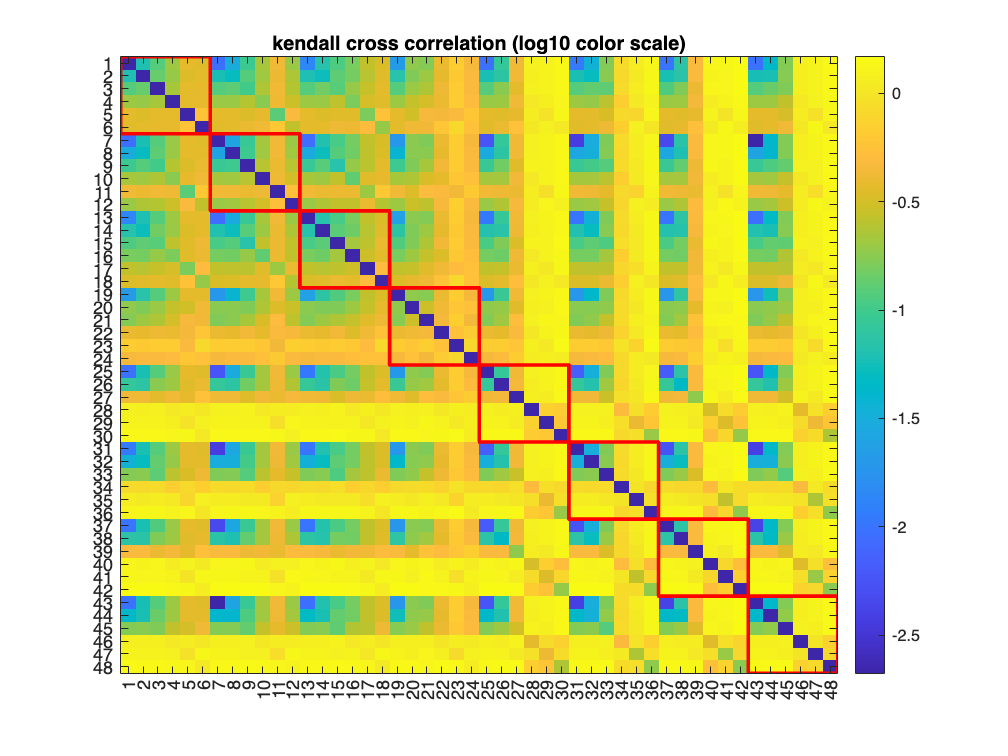

figure; imagesc(log10(-CrossCorrKendall+1)); colorbar; colormap('parula'); title("kendall cross correlation (log10 color scale)"); % surf(CrossCorrKendall); hold on;
xticks(1:48); yticks(1:48); xticklabels(1:48); yticklabels(1:48)
[nRows, nCols] = size(CrossCorrKendall); % add values
hold on; arrayfun(@(idx) plot([idx-0.5, idx+5.5, idx+5.5, idx-0.5, idx-0.5], [idx-0.5, idx-0.5, idx+5.5, idx+5.5, idx-0.5], 'r', 'LineWidth', 2), 1:6:48); hold off; % highlight same sensor data

%arrayfun(@(i, j) text(j, i, sprintf('%.3f', CrossCorrKendall(i,j)), FontSize = 10, HorizontalAlignment = 'center', Color = 'k'), repelem(1:nRows, nCols), repmat(1:nCols, 1, nRows));

CrossCorrSpearman = corr(corr_analysis_data_split', Type = 'Spearman');
disp(CrossCorrSpearman);

    1.0000    0.9917    0.9751    0.9427    0.8356    0.8098    0.9998    0.9980    0.9828    0.9417    0.7849    0.9398    0.9992    0.9895    0.9749    0.9671    0.9090    0.8260    0.9992    0.9481    0.9532    0.8062    0.5239    0.7217    0.9997    0.9882    0.7975   -0.3003   -0.4423   -0.5322    0.9996    0.9972    0.9601    0.3086   -0.2195   -0.4692    0.9997    0.9912    0.7596   -0.4077   -0.5404   -0.6075    0.9997    0.9957    0.9575   -0.2429   -0.4520   -0.5509
    0.9917    1.0000    0.9706    0.9469    0.8500    0.8037    0.9916    0.9938    0.9754    0.9439    0.8013    0.9311    0.9911    0.9919    0.9705    0.9695    0.9137    0.8187    0.9905    0.9553    0.9440    0.8175    0.5429    0.7045    0.9914    0.9904    0.8007   -0.2706   -0.4302   -0.5292    0.9915    0.9935    0.9578    0.3151   -0.1971   -0.4752    0.9915    0.9912    0.7655   -0.3903   -0.5224   -0.6052    0.9916    0.9916    0.9577   -0.2244   -0.4365   -0.5455
    0.9751    0.9706    1.0000    0.93

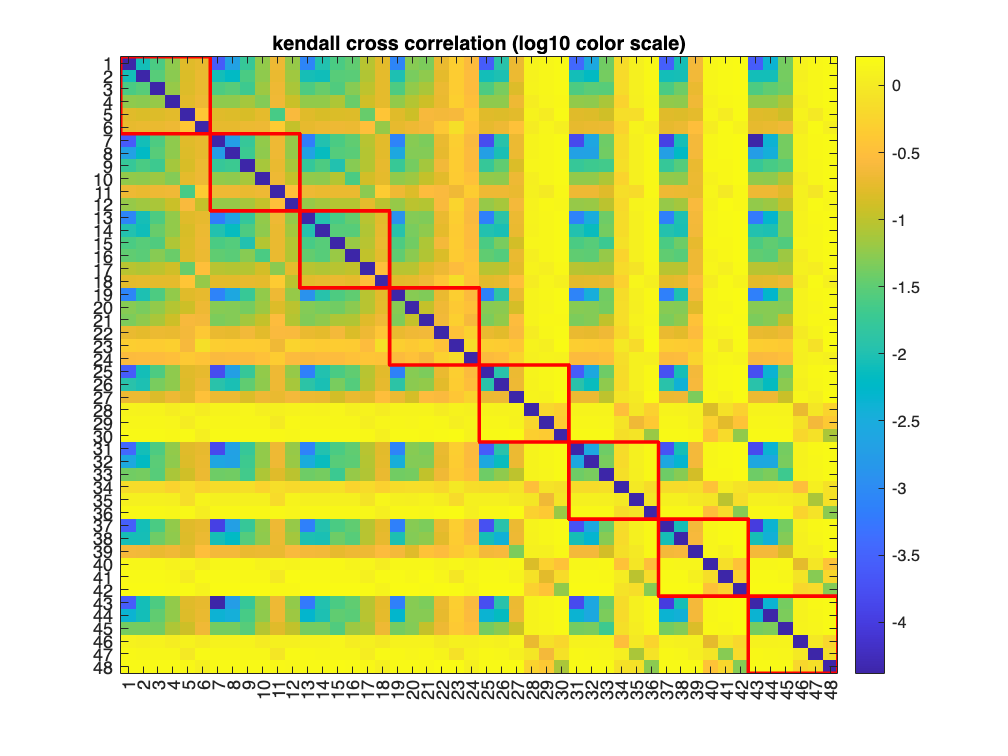

figure; imagesc(log10(-CrossCorrSpearman+1)); colorbar; colormap('parula'); title("kendall cross correlation (log10 color scale)"); % surf(CrossCorrSpearman); hold on;
xticks(1:48); yticks(1:48); xticklabels(1:48); yticklabels(1:48)
[nRows, nCols] = size(CrossCorrSpearman); % add values
hold on; arrayfun(@(idx) plot([idx-0.5, idx+5.5, idx+5.5, idx-0.5, idx-0.5], [idx-0.5, idx-0.5, idx+5.5, idx+5.5, idx-0.5], 'r', 'LineWidth', 2), 1:6:48); hold off; % highlight same sensor data

%arrayfun(@(i, j) text(j, i, sprintf('%.3f', CrossCorrSpearman(i,j)), FontSize = 10, HorizontalAlignment = 'center', Color = 'k'), repelem(1:nRows, nCols), repmat(1:nCols, 1, nRows));

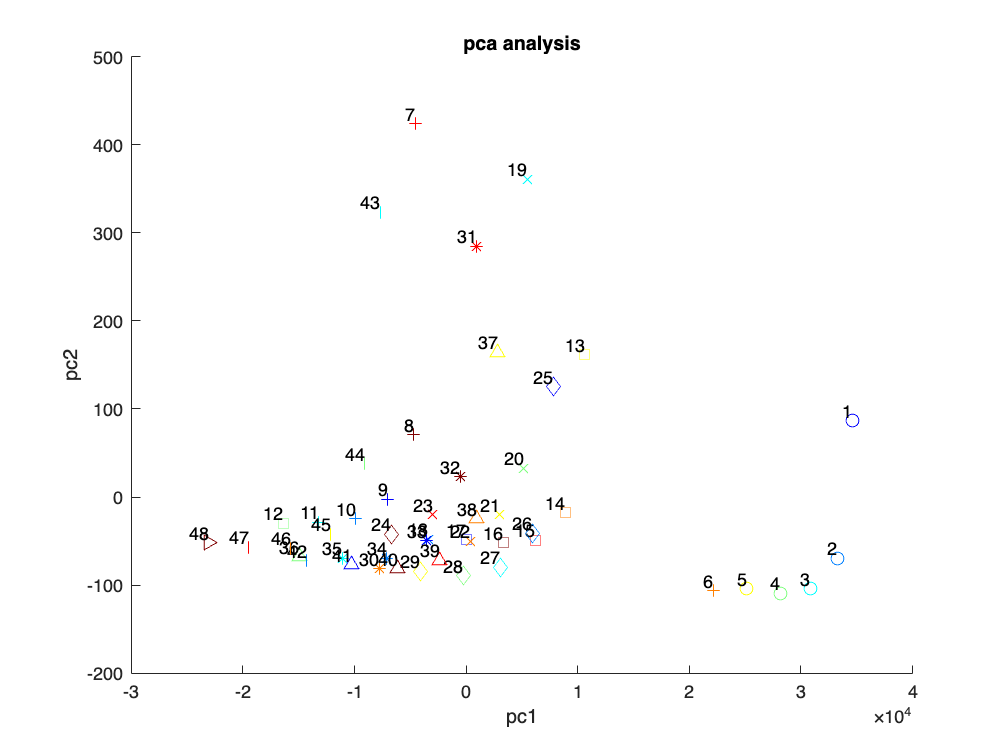

% pca analysis
[coeff, score, latent, tsquared, explained] = pca(corr_analysis_data_split);

cyclemarker = {'o', '+', 'square', 'x', 'diamond', '*', '^', '|', '>', '<', 'v', 'hexagram', '.'};
color_idx = mod((1:48) - 1, 8) + 1; % colors
colors = colmap(color_idx, :);
marker_idx = floor((1:48) / 6) + 1; % markers
markers = cyclemarker(marker_idx);

figure; hold on;
for n = 1:48
    scatter(score(n,1), score(n,2), 50, colors(n, :), Marker = markers{n});
    text(score(n,1), score(n,2), num2str(n), VerticalAlignment = 'bottom', HorizontalAlignment = 'right');
end
title("pca analysis");
xlabel("pc1");
ylabel("pc2");
hold off;

disp("pc1 (" + explained(1) + " %), pc2 (" + explained(2) + " %)")

pc1 (99.9912 %), pc2 (0.0084934 %)


pca shows us no clusters or patterns 

% tsne analysis
B_tsne2 = tsne(corr_analysis_data_split);

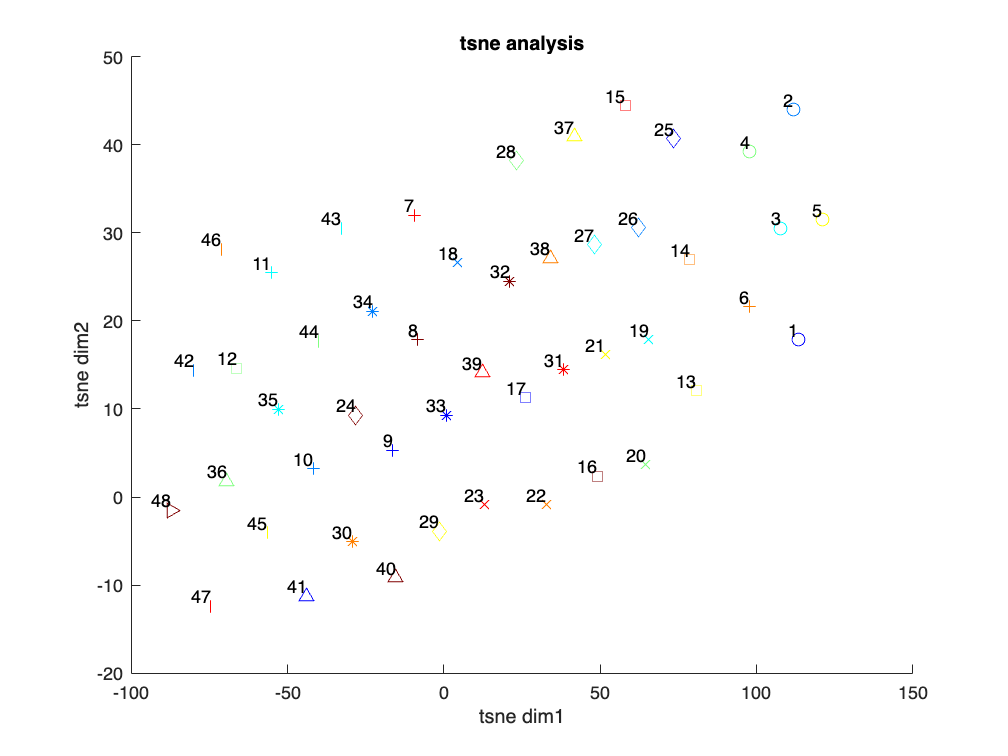

% display tsne
figure; hold on;
for n = 1:48
    scatter(B_tsne2(n,1), B_tsne2(n,2), 50, colors(n, :), Marker = markers{n});
    text(B_tsne2(n,1), B_tsne2(n,2), num2str(n), VerticalAlignment = 'bottom', HorizontalAlignment = 'right');
end
title("tsne analysis");
xlabel("tsne dim1");
ylabel("tsne dim2");

Doesnt help either...